# DSP Project 2

#### Signal Compression System Based On Sub-band Coding 

#### Group Members:

- Farshad Bolouri

- Brennae Stinson

- Anindita Das

## Introduction

A data acquisition system consisting of four microphones, placed near several quail habitats, documented calls from these species over time. Each of these microphones recorded calls which are audible through .wav files. The signals retrieved from the data acquisition system almost always contain background noise from the quail environments such as trees rustling, other animals, and wind. And depending on how close the quails were to the microphones when they made the calls, they could be heard clearly or very faintly. The objective of this project is to design a signal compression system based on sub-band coding. The signal will be split into four different frequency bands and each will be compressed by quantization of the samples.

clear
close all

% Variables for spectrogram function
F = 1000:10:3200;
window = 24000*0.04;
noverlap = round(0.8*window);

### Quail Call Characteristics

Before anything let's look at a quail call, analyze the characterisitics of it to learn more about it. This could help us with identifying the most important sub-bands (which sub-bands contain the most information about the quail calls).

[quailCall, fs] = audioread("quailCall.wav");
quailInfo = audioinfo("quailCall.wav")

quailInfo = struct with fields:
             Filename: 'C:\Users\farsh\Documents\GitHub\Digital-Signal-Processing\Project2\quailCall.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 25001
             Duration: 1.0417
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


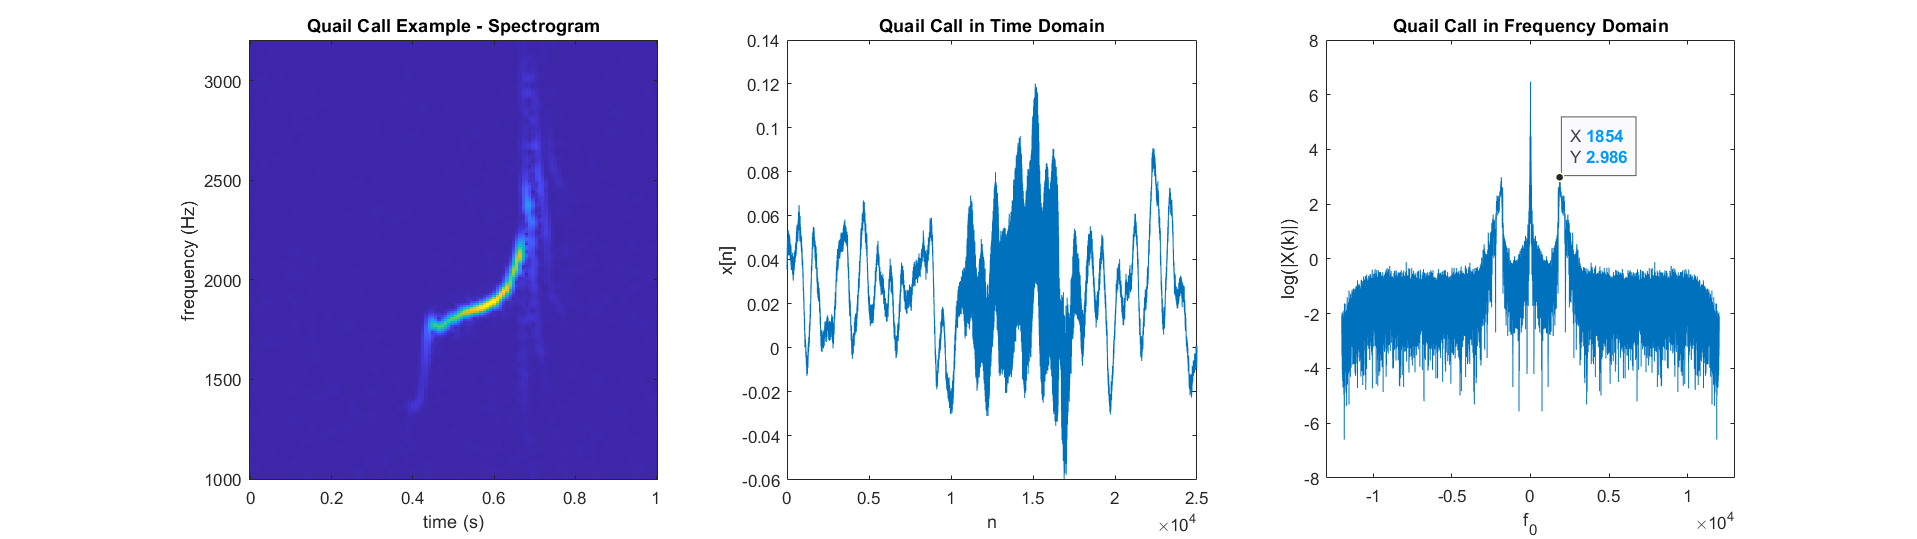

h = figure;

subplot(131);
image=spectrogram(quailCall,window,noverlap,F,fs);
imagesc(linspace(0,1,length(F)),F,abs(image))
ylabel('frequency (Hz)')
xlabel('time (s)')
set(gca,'YDir','normal')
title('Quail Call Example - Spectrogram')

subplot(132);
plot(quailCall)
xlabel('n')
ylabel('x[n]')
xlim([0 2.5e4])
title('Quail Call in Time Domain')
set(h,'Units','normalized','Position',[0 0 1 .5]); 

subplot(133);
fourierQuail = log(abs (fftshift(fft(quailCall))));             % Zero-Centered FFT
f0Quail = (-quailInfo.TotalSamples/2:quailInfo.TotalSamples/2-1)...
    /quailInfo.TotalSamples*fs;                                 % Zero-Centered Frequency Range
plot(f0Quail, fourierQuail)
ylabel('log(|X(k)|)')
xlabel('f_{0}');
xlim([-1.3e4 1.3e4])
title('Quail Call in Frequency Domain')
% axes 3
ax = gca;
chart = ax.Children(1);
datatip(chart,1854,2.986);

After inspecting the call in these plots, we concluded that even though the signature of the call is starting anywhere around the 1000-1500 Hz range up to 3200 Hz range, the main part of the call that we are intereseted in is between 1850 Hz to 2400 Hz. *(The yellow color in the spectrogram - This frequency range is what we hear and recogize as a "Quail Call" when listenning to the audio files)****.***

### Loading and Visualzing the Input Signal

[inputSig, Fs] = audioread('quailCall_middle.wav');
inputInfo = audioinfo('quailCall_middle.wav')

inputInfo = struct with fields:
             Filename: 'C:\Users\farsh\Documents\GitHub\Digital-Signal-Processing\Project2\quailCall_middle.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 240001
             Duration: 10.0000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


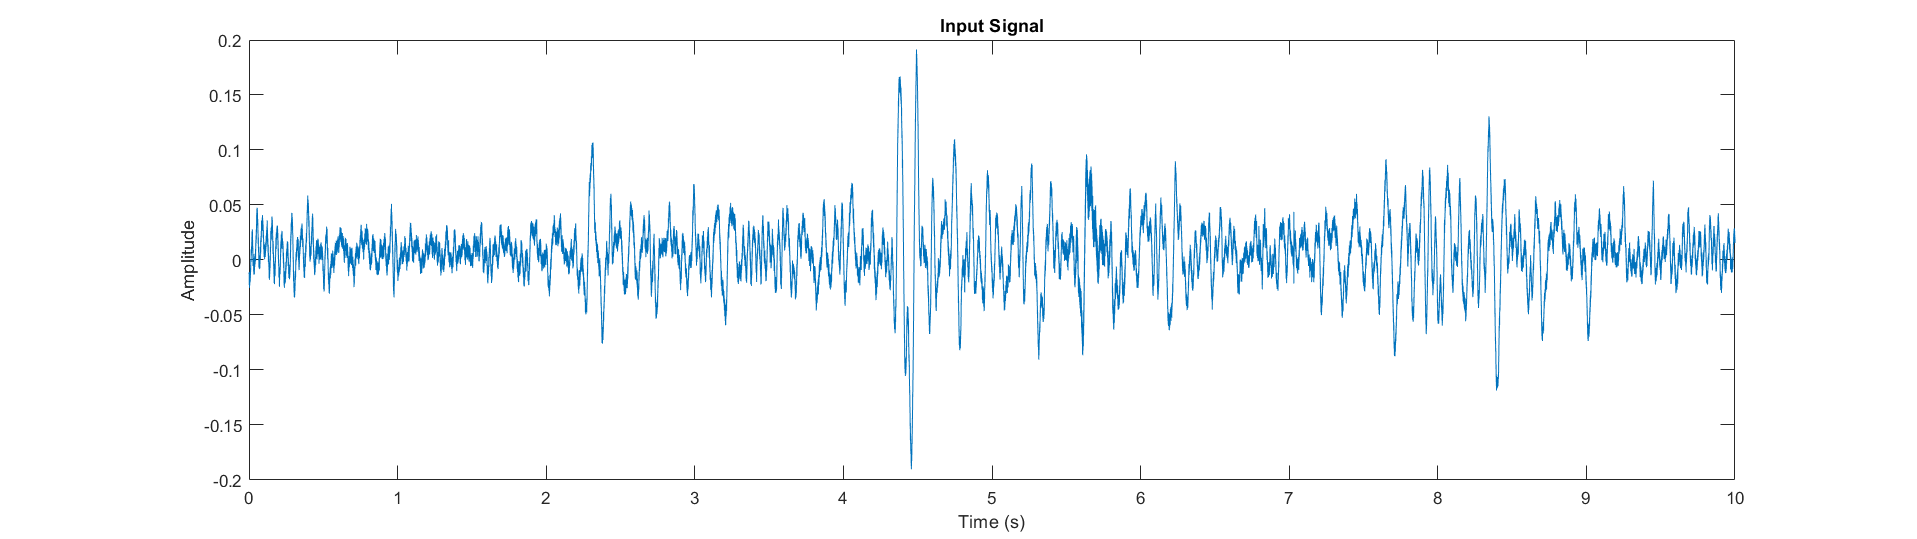

timeInput = linspace(0, inputInfo.Duration, inputInfo.TotalSamples);
h = figure;
plot(timeInput, inputSig)
title('Input Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .5]);

Now let's listen to this signal:

*(If you would prefer to not listen to this audio file, don't run this section or comment it out :) )*

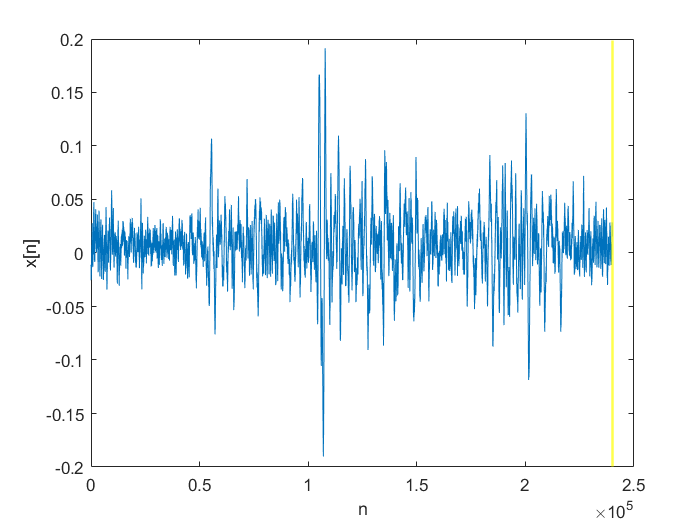

player = audioplayer(inputSig,Fs);
figure
plot(inputSig)
xlabel('n')
ylabel('x[n]')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player);
for i = 1:length(inputSig)/2400
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

The call can be heard in the middle of the audio file as demonstrated above.

Let's look at the signal in the frequency domain:

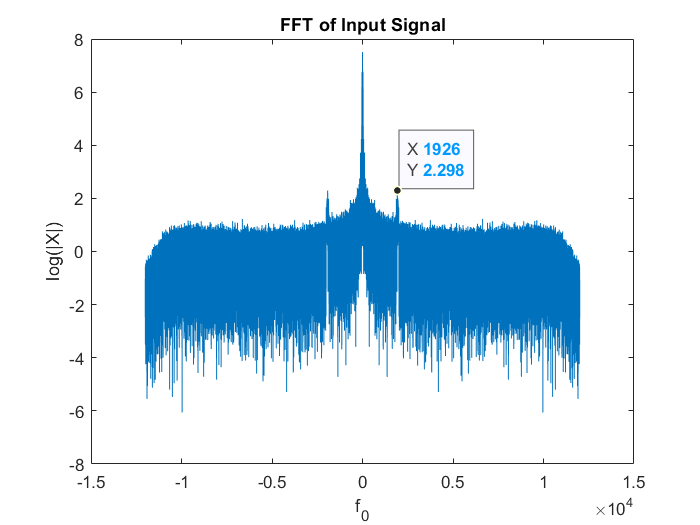

h = figure;
inputFFT = log(abs (fftshift(fft(inputSig))));                  % Zero-Centered FFT
f0Input = (-inputInfo.TotalSamples/2:inputInfo.TotalSamples/2-1)...
    /inputInfo.TotalSamples*Fs;                                 % Zero-Centered Frequency Range
plot(f0Input, inputFFT)
title('FFT of Input Signal');
ylabel('log(|X|)')
xlabel('f_{0}');
ax = gca;
chart = ax.Children(1);
datatip(chart,1926,2.298);

As you can see the strength of the quail call here is not as much as the quail call demonstrated before. That's just due to the quail being farther away from the microphone in the time of the recording. But we still can clearly identify our target frequency.

## The Encoder

The encoder consists of an analysis filter band and a quantizer per subband. The analysis filter bank consists of concatenated lowpass and highpass filters, where ${\mathrm{H}}_0 \left(z\right)$ is a lowpass filter and ${\mathrm{H}}_1 \left(z\right)$ a highpass filter, see figure below. The structure provides a finer frequency resolution at lower frequencies. 

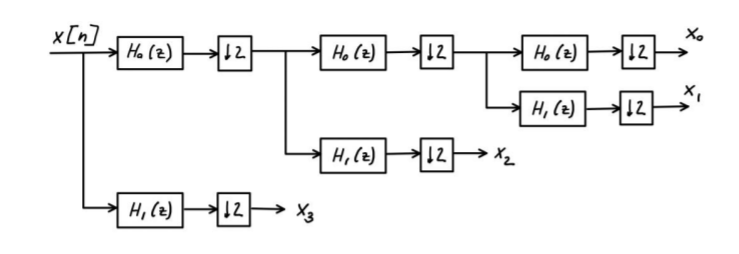

### Designing the Filters

#### First ${\mathrm{H}}_0 \left(z\right)$:

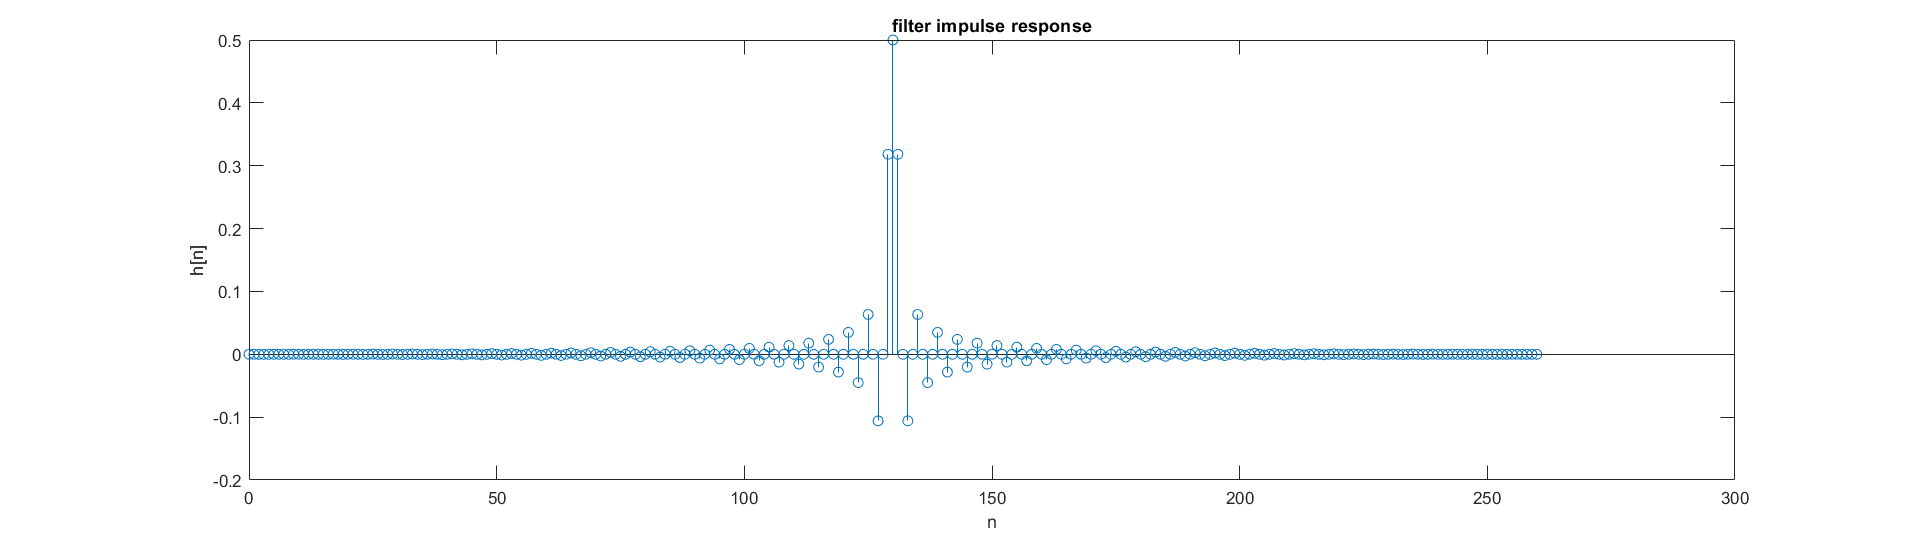

% FIR Window Lowpass filter designed using the FIR1 function.

% All frequency values are in Hz.

Fpass = 5800;              % Passband Frequency
Fstop = 6200;              % Stopband Frequency
Dpass = 0.057501127785;    % Passband Ripple
Dstop = 0.00031622776602;  % Stopband Attenuation
flag  = 'scale';           % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fpass Fstop]/(Fs/2), [1 0], [Dstop Dpass]);

% Calculate the coefficients using the FIR1 function.
hLP1  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
LP_6K = dfilt.dffir(hLP1);

% graph filter impulse response
graph = figure;
stem(0:length(hLP1)-1,hLP1)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

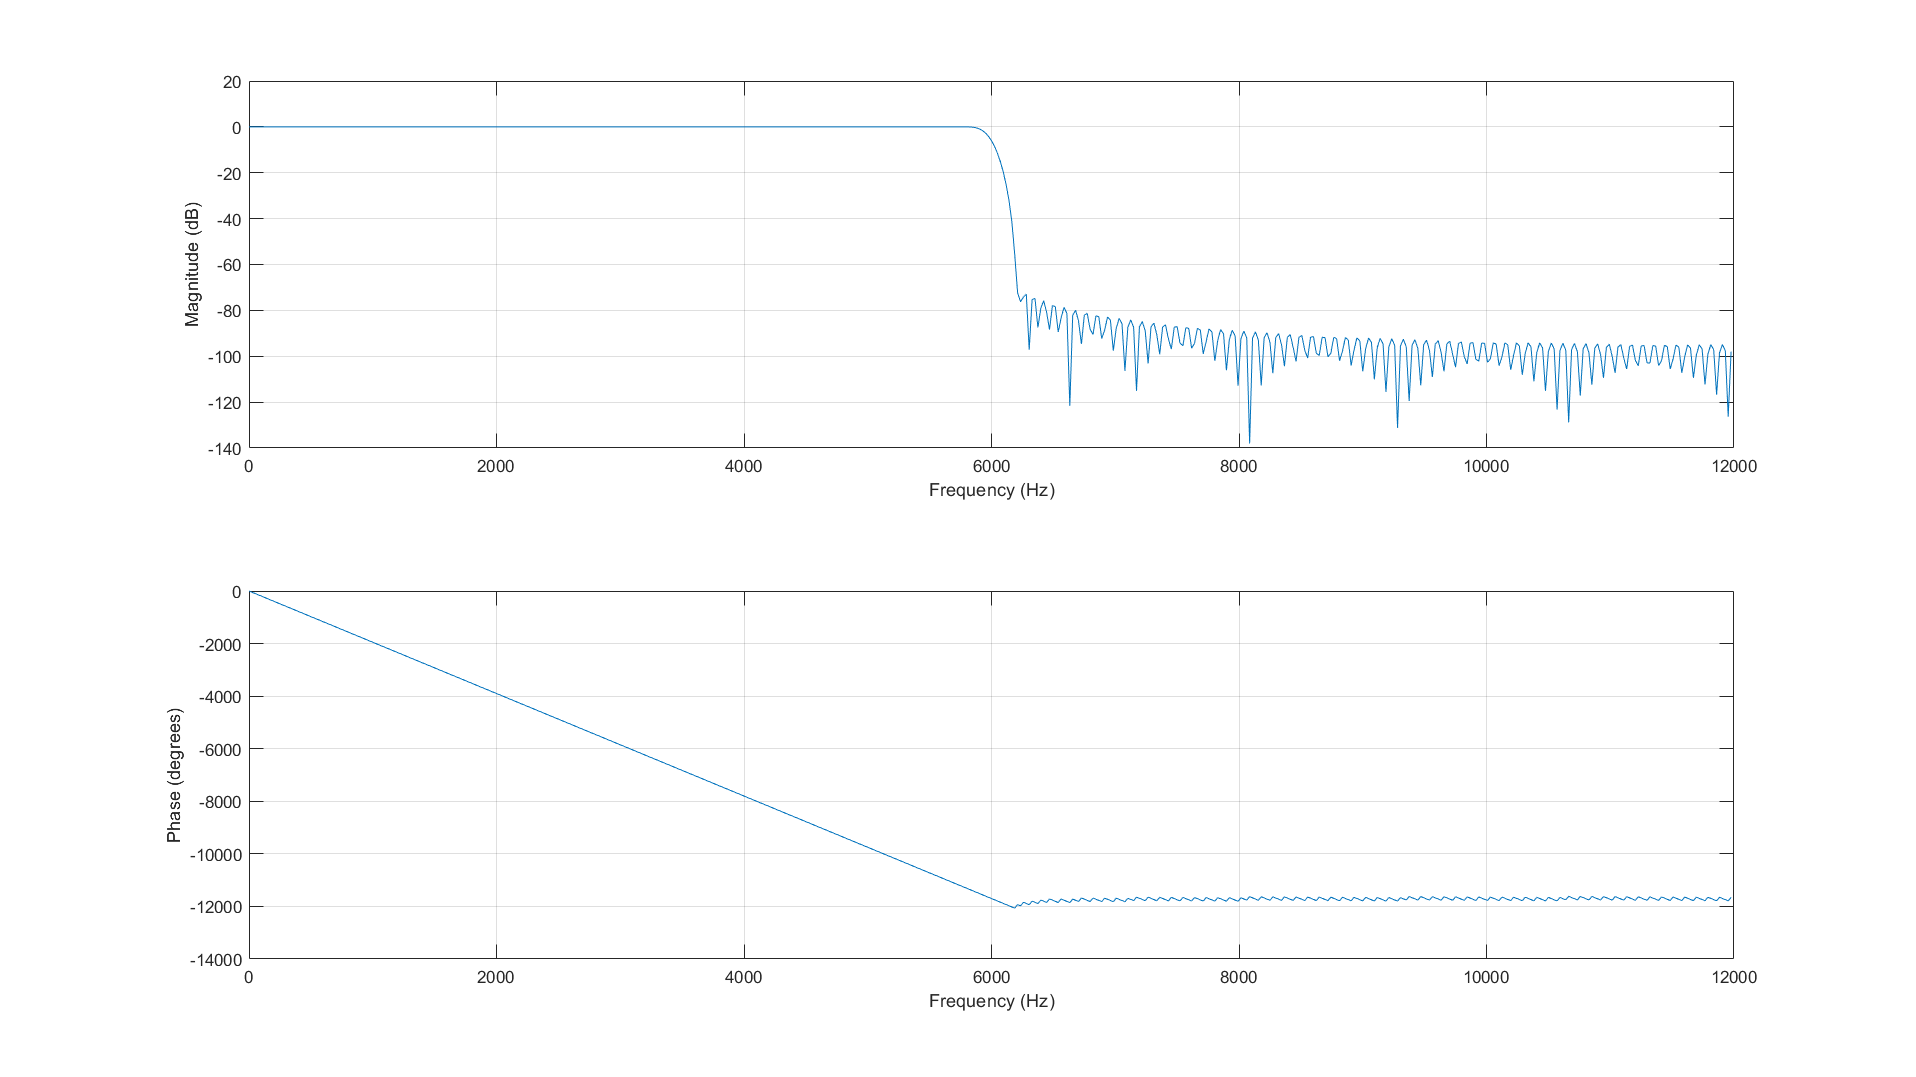

% graph filter frequency response
graph = figure;
freqz(hLP1,1,[],Fs)
set(graph,'Units','normalized','Position',[0 0 1 1]);

We chose our passband ripple to be 1 dB because we didn't want too much fluctuations in the frequencies that we are trying to keep. We put the stopband attenuation to 70 dB  as we found it to be enough to remove the frequecies that we don't want.

Our $f_s$ is at 24000 Hz as this is the sampling frequency of our input signal.

We put our $f_c$ to 6000 Hz and the way we calculated this $f_c$ was : $\frac{\frac{f_s }{2}}{M}=\frac{\frac{24000}{2}\;\textrm{Hz}}{2}=6000\;\textrm{Hz}$. ($M$ being the decimating factor.)

We used a Kaiser window for designing the FIR filter, as we has the option to design the filter with "Minimum Order" conditions while maintaining the desired attributes of the filter. The order of the filter was calculated to be **260**.

#### First ${\mathrm{H}}_1 \left(z\right)$:

As we are trying split the input signal to two signals, one containing the lower half of the representable frequencies, and the second one, the upper half of the frequencies, we need to design our first highpass filter with the same conditions as our first lowpass to provide the best results.

Here's the cooresponding Highpass filter:

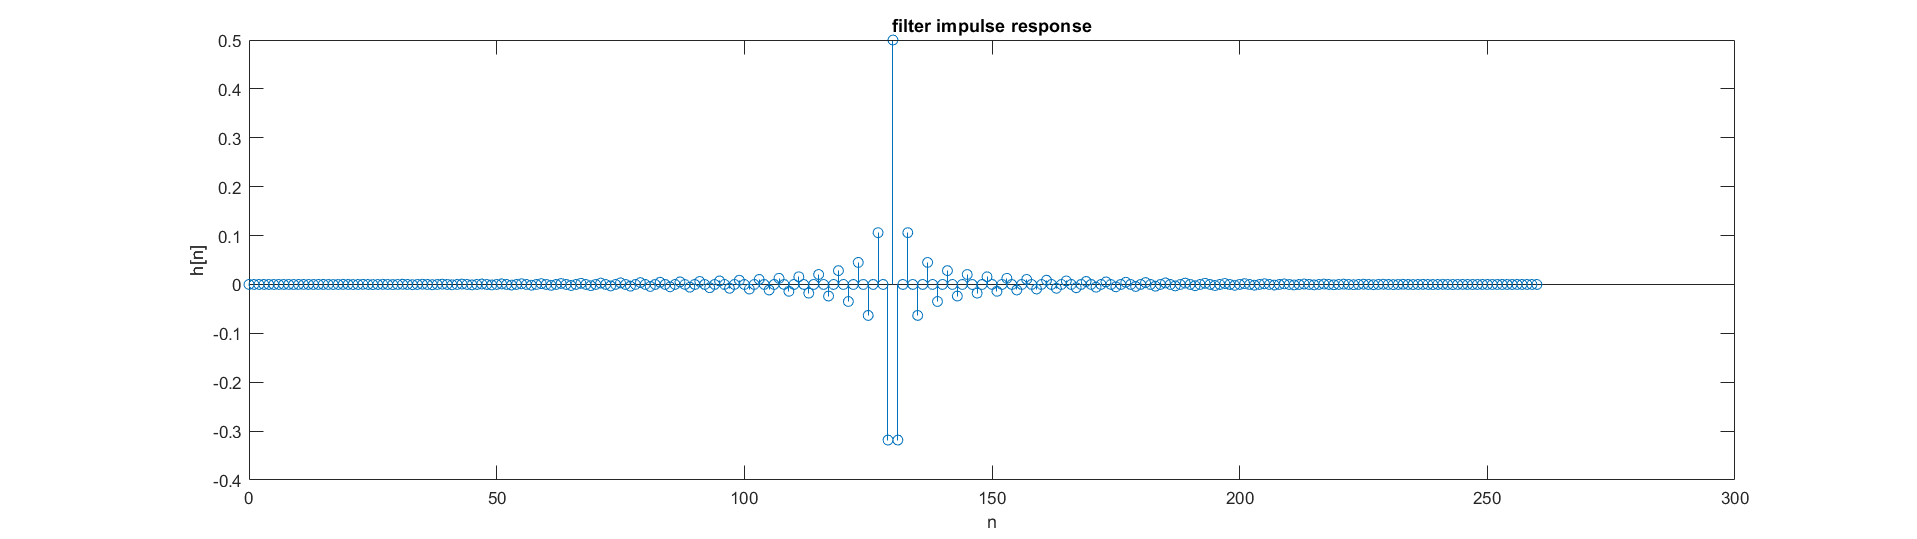

Fstop = 5800;              % Stopband Frequency
Fpass = 6200;              % Passband Frequency
Dstop = 0.00031622776602;  % Stopband Attenuation
Dpass = 0.057501127785;    % Passband Ripple
flag  = 'scale';           % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fstop Fpass]/(Fs/2), [0 1], [Dpass Dstop]);

% Calculate the coefficients using the FIR1 function.
hHP1  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
HP_6K = dfilt.dffir(hHP1);

% graph filter impulse response
graph = figure;
stem(0:length(hHP1)-1,hHP1)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

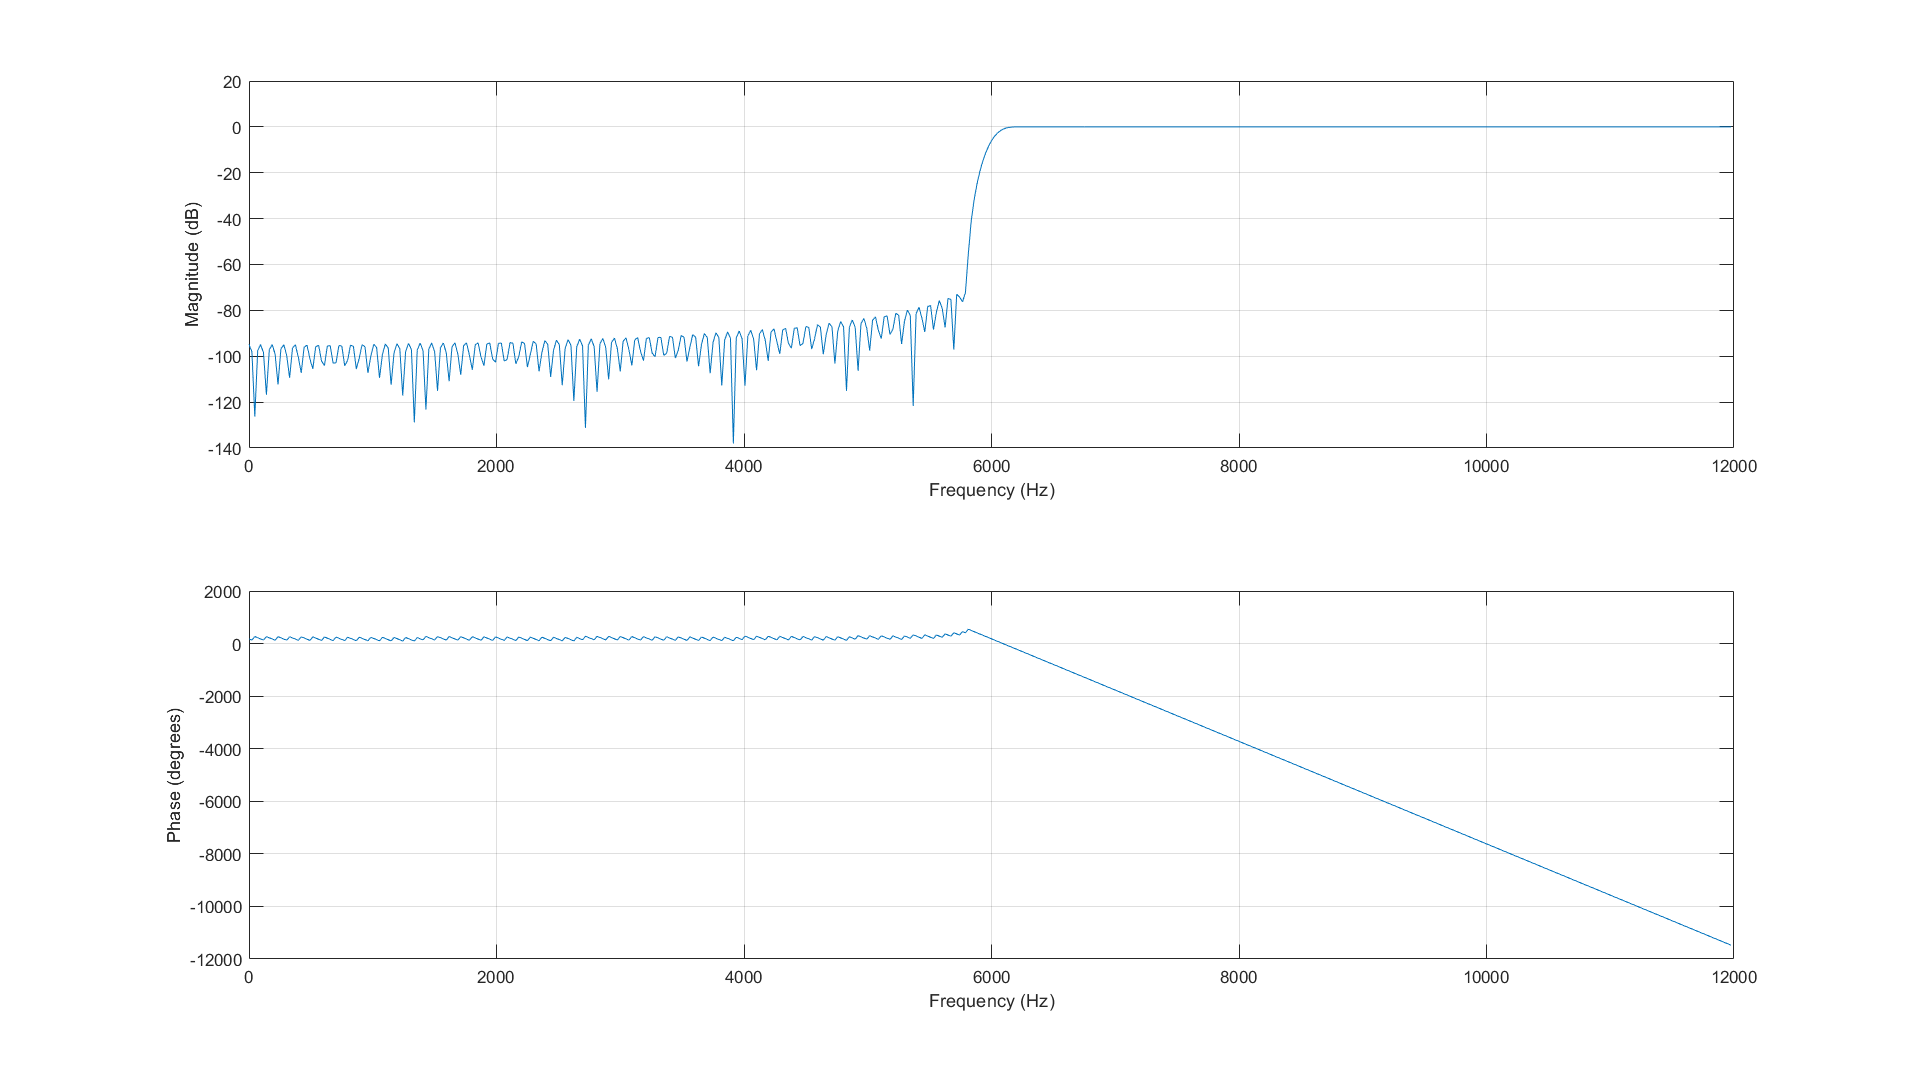

% graph filter frequency response
graph = figure;
freqz(hHP1,1,[],Fs)
set(graph,'Units','normalized','Position',[0 0 1 1]);

#### Second ${\mathrm{H}}_0 \left(z\right)$:

% FIR Window Lowpass filter designed using the FIR1 function.

% All frequency values are in Hz.
Fs2 = 12000;  % Sampling Frequency

Fpass = 2900;              % Passband Frequency
Fstop = 3100;              % Stopband Frequency
Dpass = 0.057501127785;    % Passband Ripple
Dstop = 0.00031622776602;  % Stopband Attenuation
flag  = 'scale';           % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fpass Fstop]/(Fs2/2), [1 0], [Dstop Dpass]);

% Calculate the coefficients using the FIR1 function.
hLP2  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
LP_3K = dfilt.dffir(hLP2);

% graph filter impulse response
graph = figure;
stem(0:length(hLP2)-1,hLP2)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

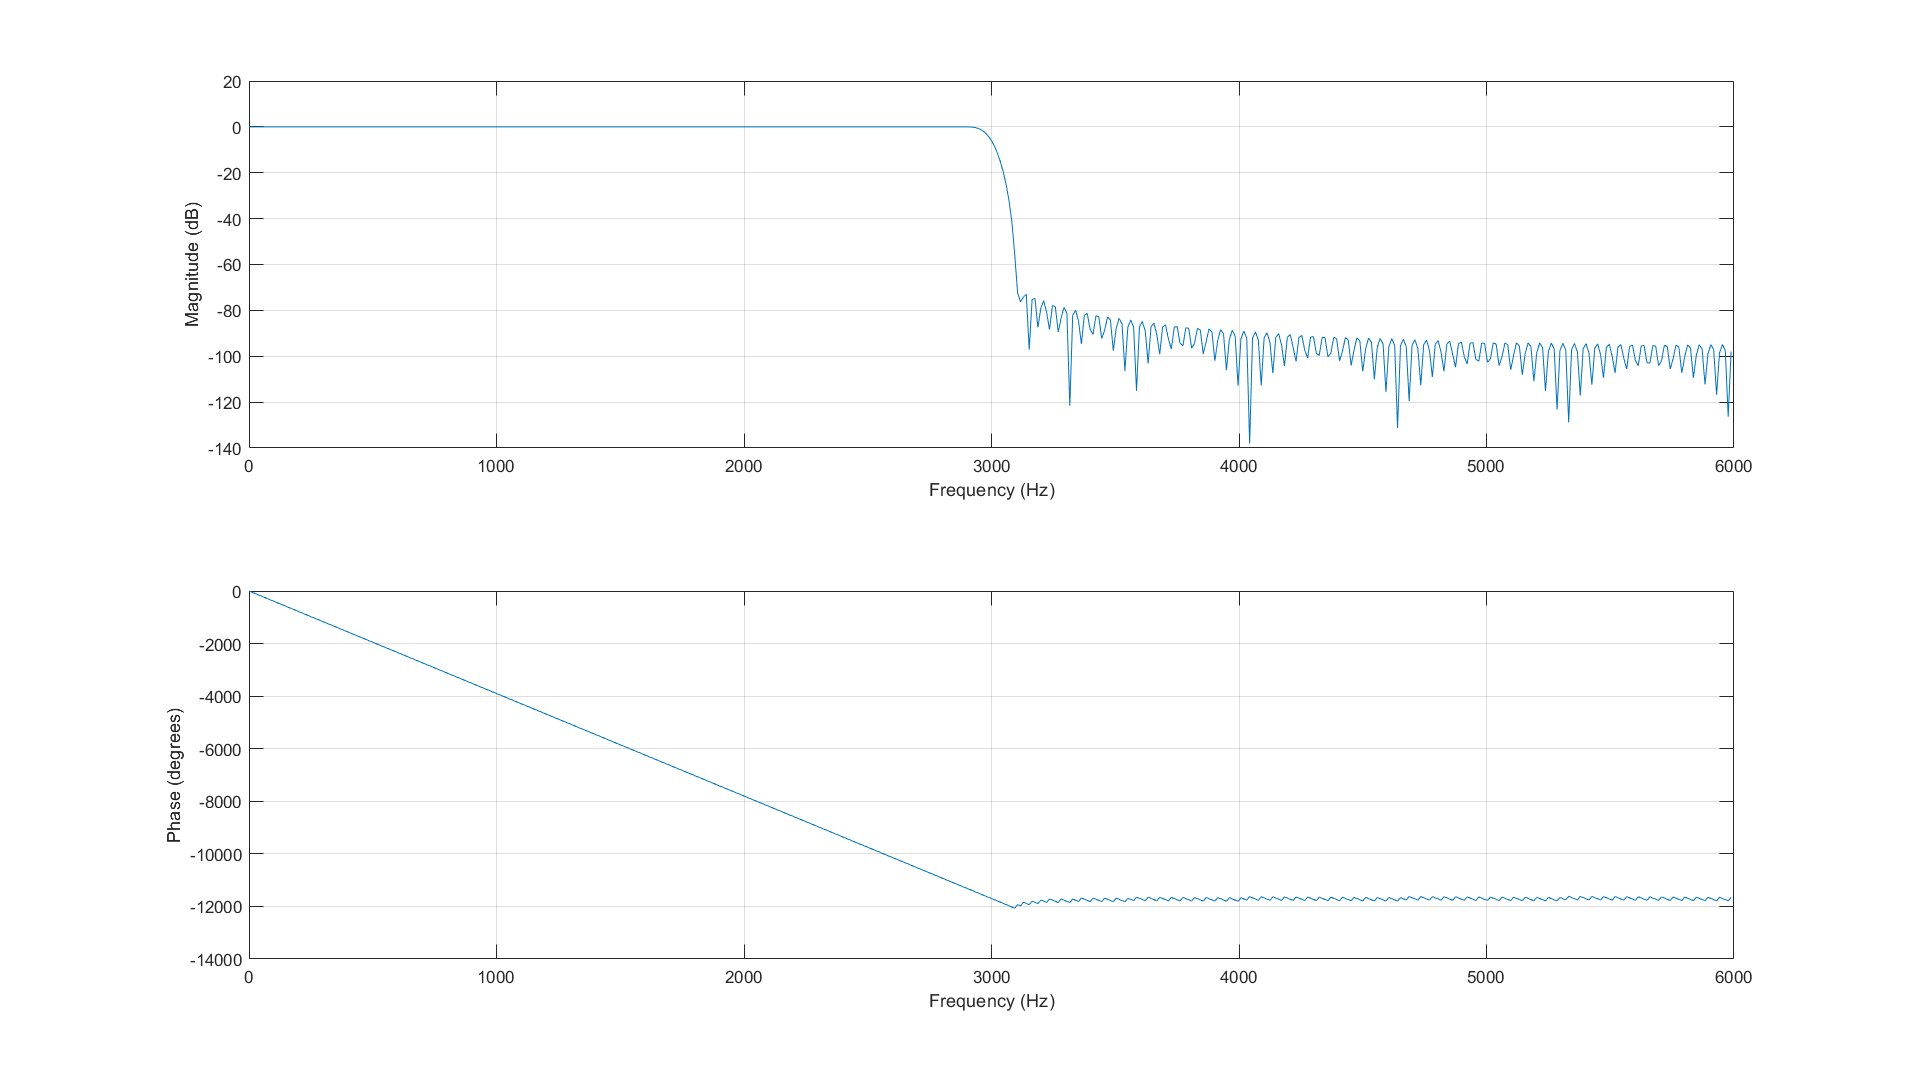

% graph filter frequency response
graph = figure;
freqz(hLP2,1,[],Fs2)
set(graph,'Units','normalized','Position',[0 0 1 1]);

We chose our passband ripple and stopband attenuation to again be 1dB and 70dB respectively for the same reasons as before.

Our new $f_s$ is at 12000 Hz as now the sampling frequency of our input signal after the applying the previous filters is now reduced to half.

We put our new $f_c$ to 3000 Hz and the way we calculated this $f_c$ was again: $\frac{\frac{f_s }{2}}{M}=\frac{\frac{12000}{2}\;\textrm{Hz}}{2}=3000\;\textrm{Hz}$. ($M$ being the decimating factor.)

We used a Kaiser window for designing the FIR filter, as we has the option to design the filter with "Minimum Order" conditions while maintaining the desired attributes of the filter. The order of the filter was again calculated to be **260**.

#### Second ${\mathrm{H}}_1 \left(z\right)$:

% All frequency values are in Hz.

Fstop = 2900;              % Stopband Frequency
Fpass = 3100;              % Passband Frequency
Dstop = 0.00031622776602;  % Stopband Attenuation
Dpass = 0.057501127785;    % Passband Ripple
flag  = 'scale';           % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fstop Fpass]/(Fs2/2), [0 1], [Dpass Dstop]);

% Calculate the coefficients using the FIR1 function.
hHP2  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
HP_3K = dfilt.dffir(hHP2);

% graph filter impulse response
graph = figure;
stem(0:length(hHP2)-1,hHP2)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

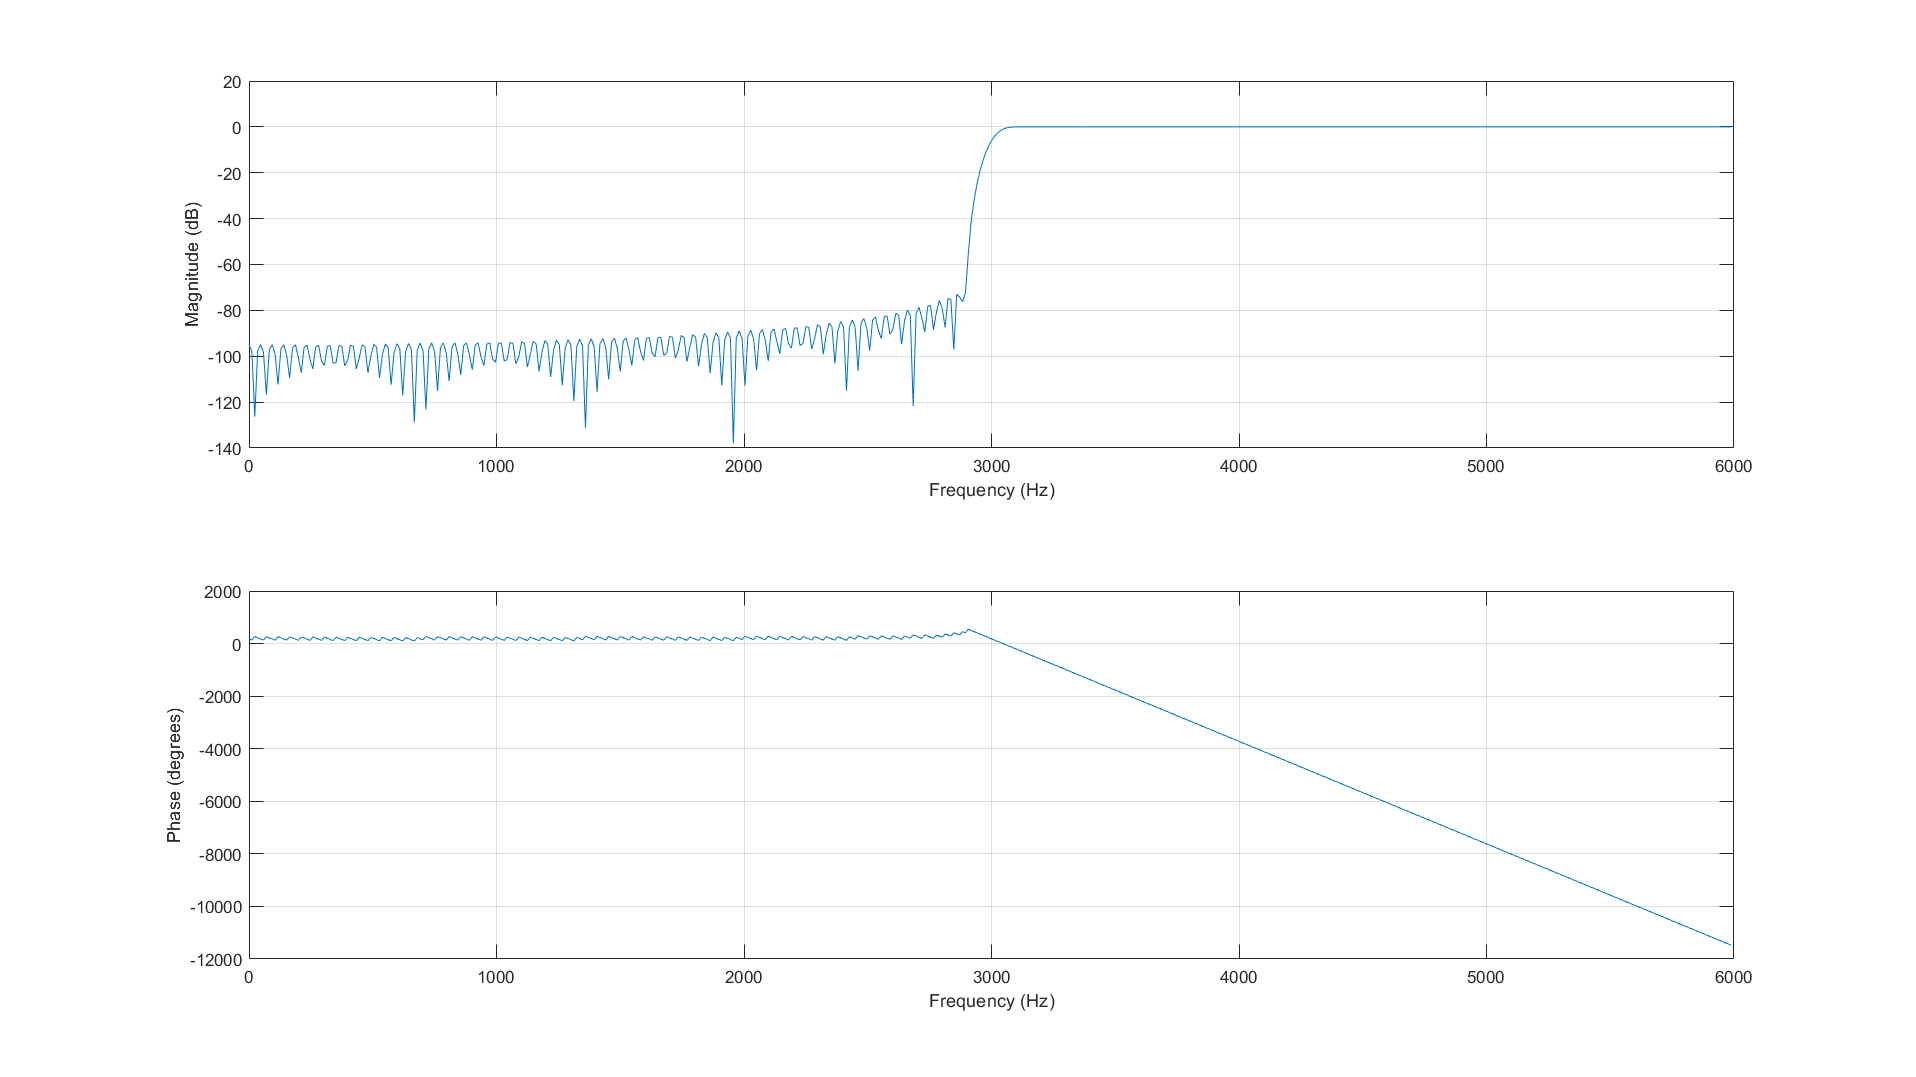

% graph filter frequency response
graph = figure;
freqz(hHP2,1,[],Fs2)
set(graph,'Units','normalized','Position',[0 0 1 1]);

#### Third ${\mathrm{H}}_0 \left(z\right)$:

% FIR Window Lowpass filter designed using the FIR1 function.

% All frequency values are in Hz.
Fs3 = 6000;  % Sampling Frequency

Fpass = 1450;              % Passband Frequency
Fstop = 1550;              % Stopband Frequency
Dpass = 0.057501127785;    % Passband Ripple
Dstop = 0.00031622776602;  % Stopband Attenuation
flag  = 'scale';           % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fpass Fstop]/(Fs3/2), [1 0], [Dstop Dpass]);

% Calculate the coefficients using the FIR1 function.
hLP3  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
LP_1500 = dfilt.dffir(hLP3);

% graph filter impulse response
graph = figure;
stem(0:length(hLP3)-1,hLP3)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

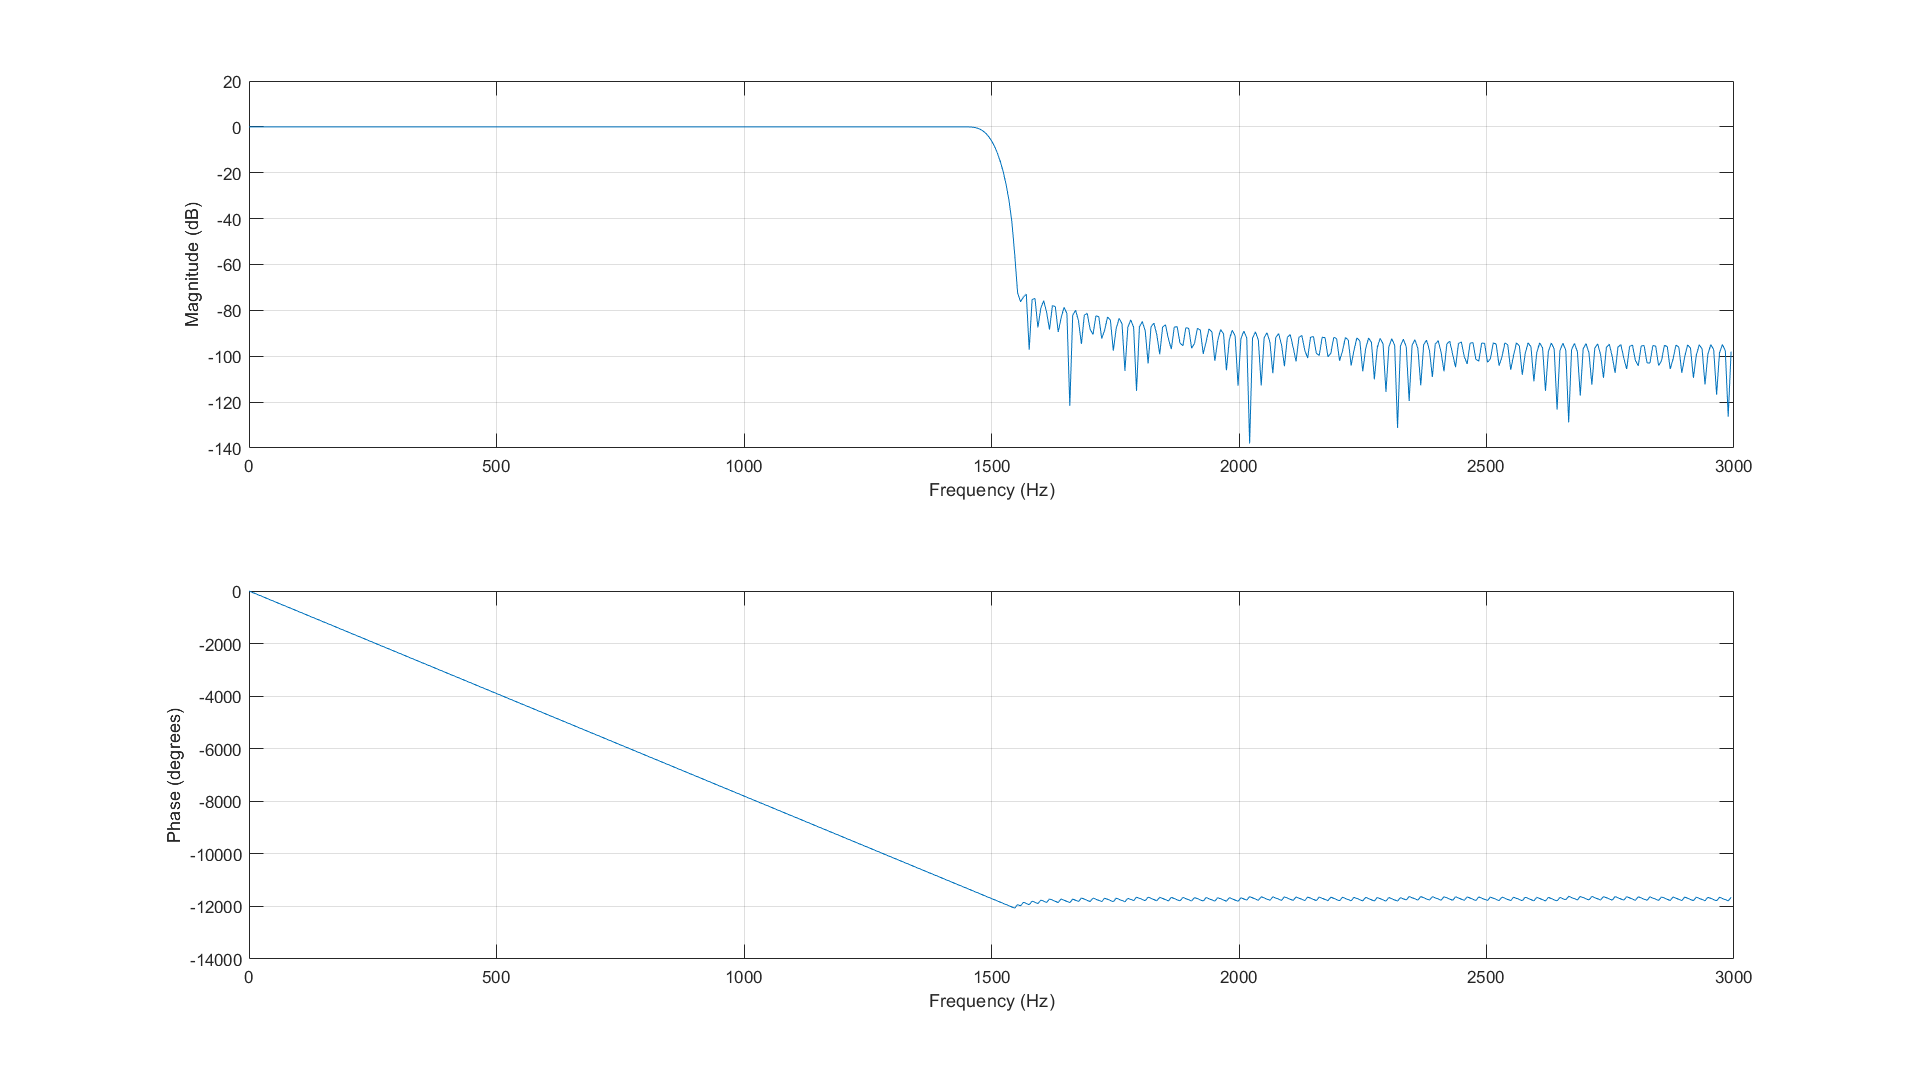

% graph filter frequency response
graph = figure;
freqz(hLP3,1,[],Fs3)
set(graph,'Units','normalized','Position',[0 0 1 1]);

We chose our passband ripple and stopband attenuation to again be 1dB and 70dB respectively for the same reasons as before.

Our new $f_s$ is at 6000 Hz as now the sampling frequency of our input signal after the applying the previous filters is now reduced to half.

We put our new $f_c$ to 1500 Hz and the way we calculated this $f_c$ was again: $\frac{\frac{f_s }{2}}{M}=\frac{\frac{6000}{2}\;\textrm{Hz}}{2}=1500\;\textrm{Hz}$. ($M$ being the decimating factor.)

We used a Kaiser window for designing the FIR filter, as we has the option to design the filter with "Minimum Order" conditions while maintaining the desired attributes of the filter. The order of the filter was again, as expected, calculated to be **260**.

#### Third ${\mathrm{H}}_1 \left(z\right)$:

Fstop = 1450;              % Stopband Frequency
Fpass = 1550;              % Passband Frequency
Dstop = 0.00031622776602;  % Stopband Attenuation
Dpass = 0.057501127785;    % Passband Ripple
flag  = 'scale';           % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fstop Fpass]/(Fs3/2), [0 1], [Dpass Dstop]);

% Calculate the coefficients using the FIR1 function.
hHP3  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
HP_1500 = dfilt.dffir(hHP3);

% graph filter impulse response
graph = figure;
stem(0:length(hHP3)-1,hHP3)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

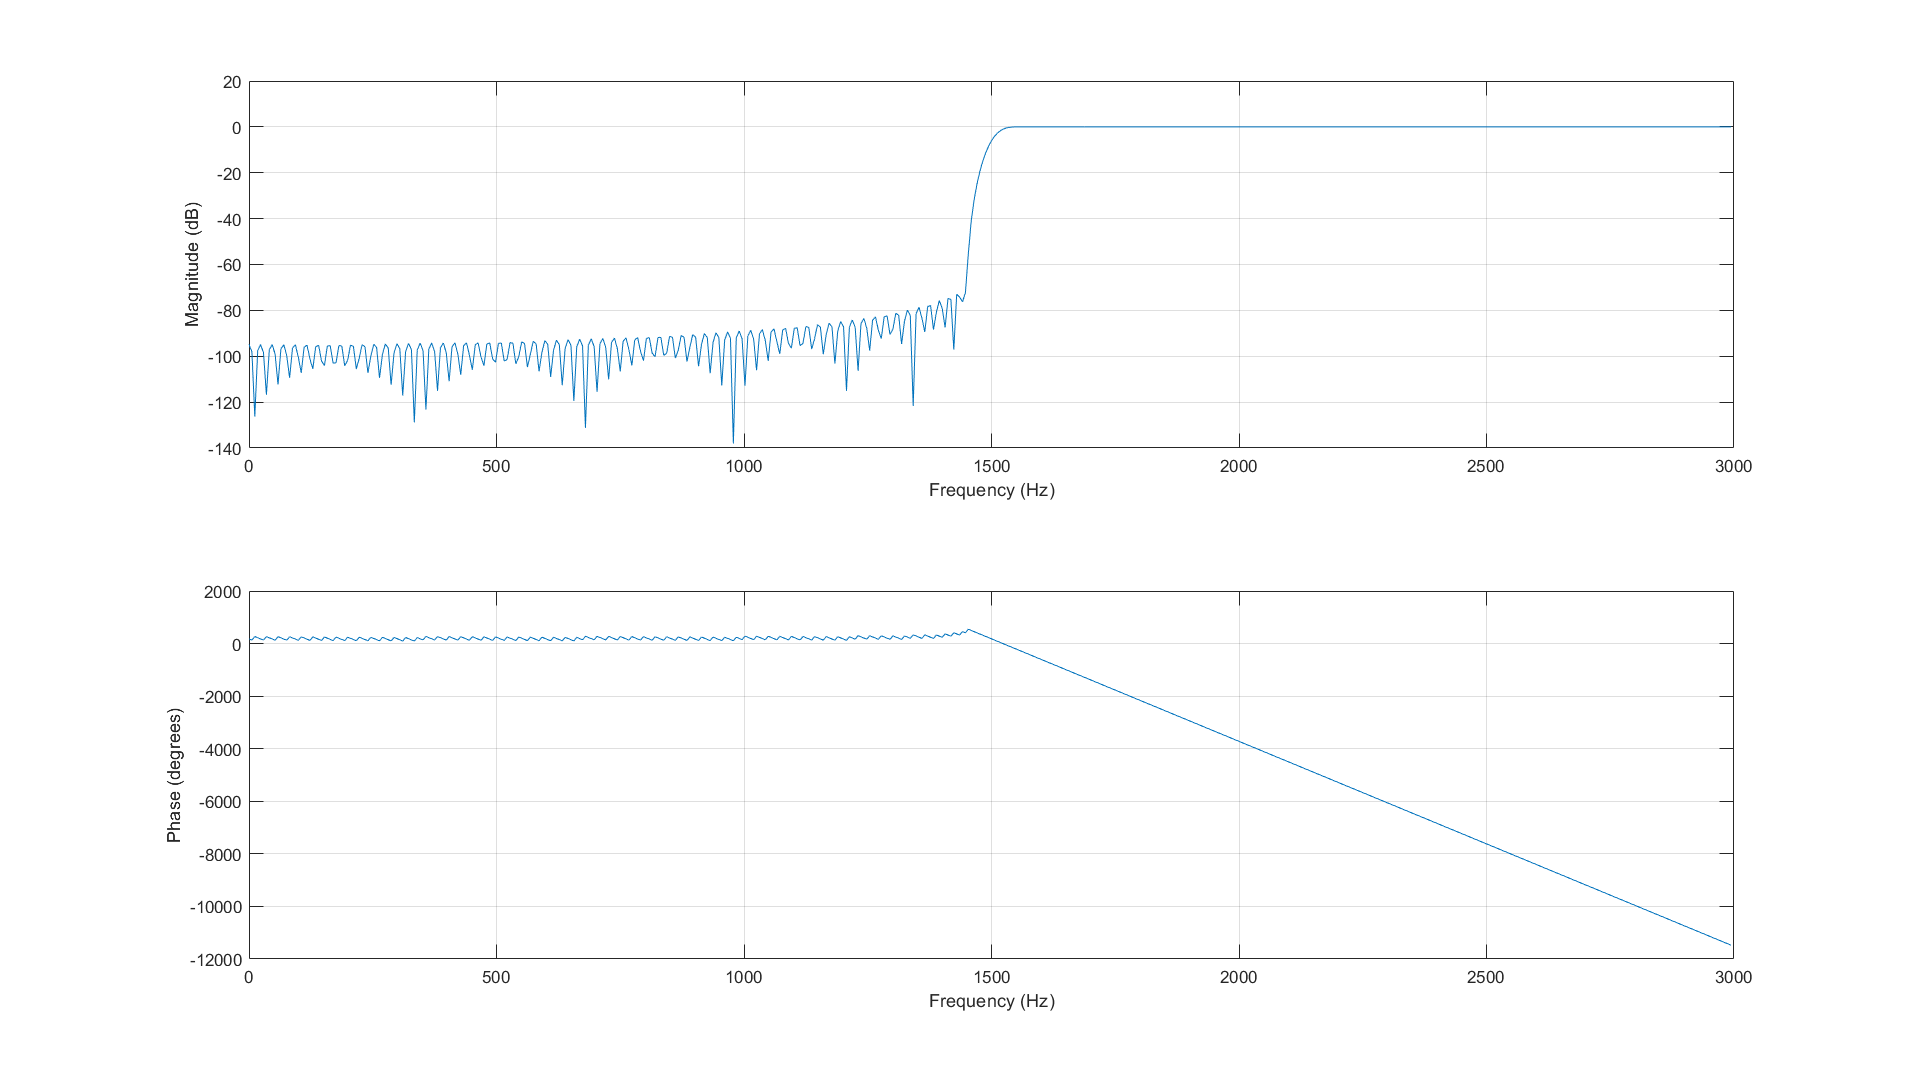

% graph filter frequency response
graph = figure;
freqz(hHP3,1,[],Fs3)
set(graph,'Units','normalized','Position',[0 0 1 1]);

### Decimation using the Filters

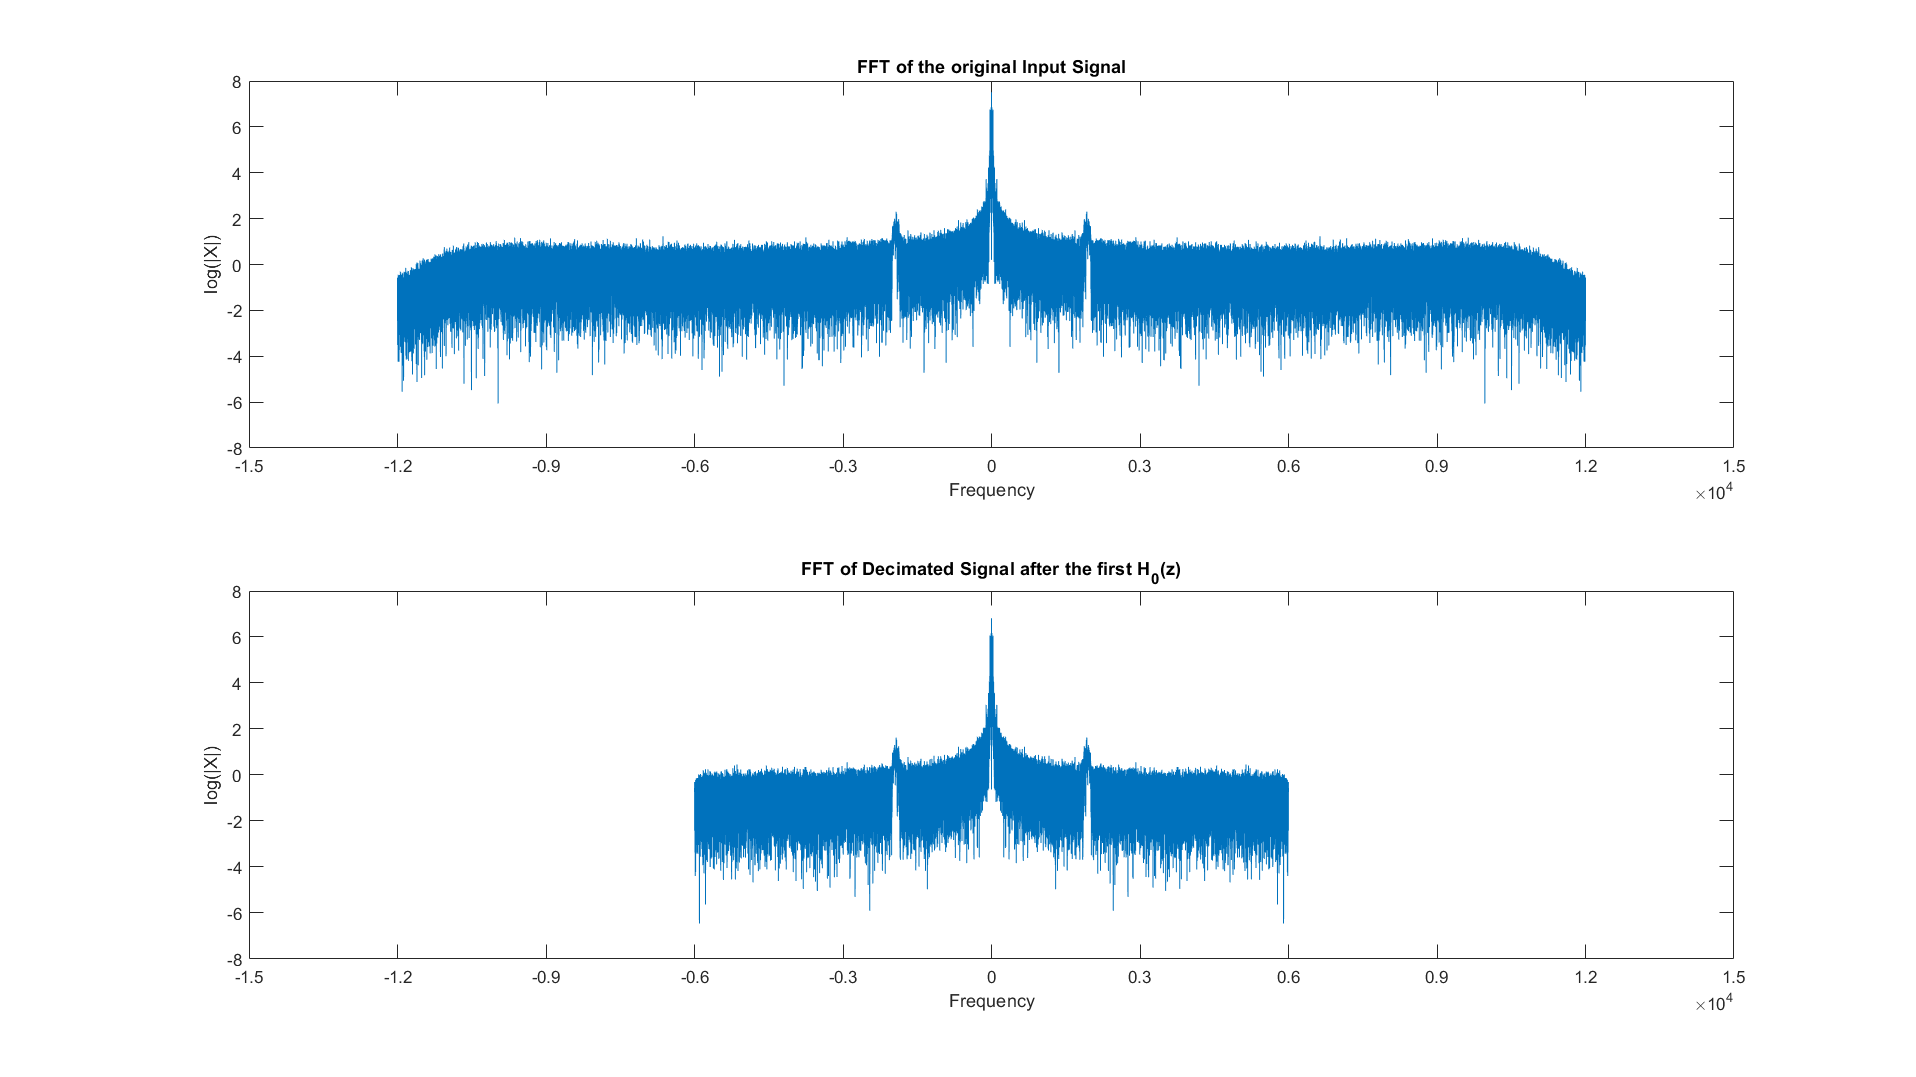

filteredSigLP1 = filter(LP_6K, inputSig);

M = 2;   % Decimating Factor
decimatedSigLP1= filteredSigLP1(1:M:end);

audiowrite("decimatedSigLP1.wav", decimatedSigLP1, Fs2);

decimatedSigLP1FFT = log(abs(fftshift(fft(decimatedSigLP1))));     % Zero-Centered FFT
decimatedSigLP1F = (-length(decimatedSigLP1)/2:...
    length(decimatedSigLP1)/2-1)...
    /length(decimatedSigLP1)*Fs2;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigLP1F, decimatedSigLP1FFT)
title('FFT of Decimated Signal after the first H_0(z)');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

*You can see how the frequency range has changed from [-12000  12000 Hz] to [-6000 6000 Hz] which represents the lower frequency band of the signal. As you can see we are still seeing the quail call signature as it exists in this frequency range.*

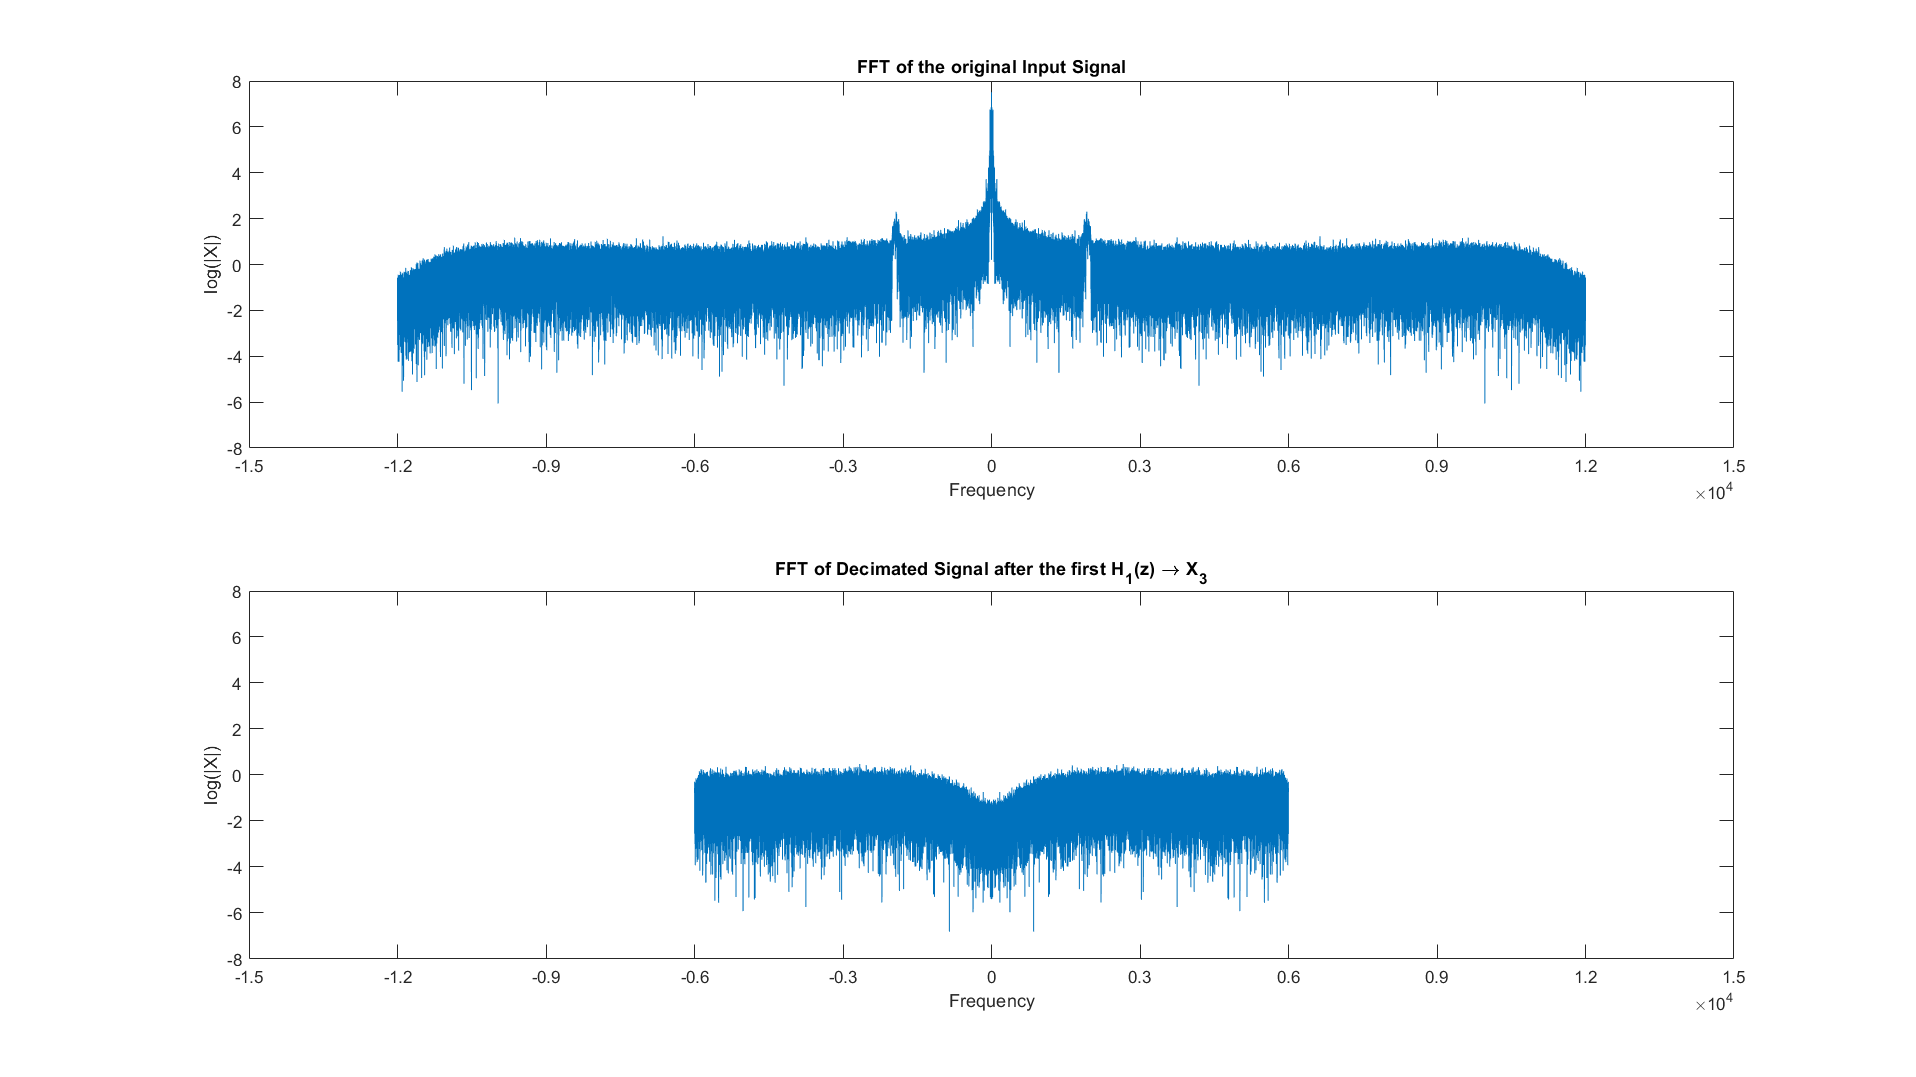

filteredSigHP1 = filter(HP_6K, inputSig);

decimatedSigHP1= filteredSigHP1(1:M:end);

audiowrite("decimatedSigHP1.wav", decimatedSigHP1, Fs2);

decimatedSigHP1FFT = log(abs(fftshift(fft(decimatedSigHP1))));     % Zero-Centered FFT
decimatedSigHP1F = (-length(decimatedSigHP1)/2:...
    length(decimatedSigHP1)/2-1)...
    /length(decimatedSigHP1)*Fs2;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigHP1F, decimatedSigHP1FFT)
title('FFT of Decimated Signal after the first H_1(z) \rightarrow X_3');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

You can see how the frequency range has now changed same as the last filtering process. However the frequencies shown above are not actually representing the frequencies [-6000 6000] of the actual input signal.  You are seeing the frequencies from 12-24 kHz being shifted to -12-0 kHz and those from -24- -12 kHz being shifted to 0-12 kHz.

They're actually representing the frequencies [-12000 -6000] and [6000 12000] as this decimation process is actually preserving the higher frequencies. The graph below demonstrates this better.

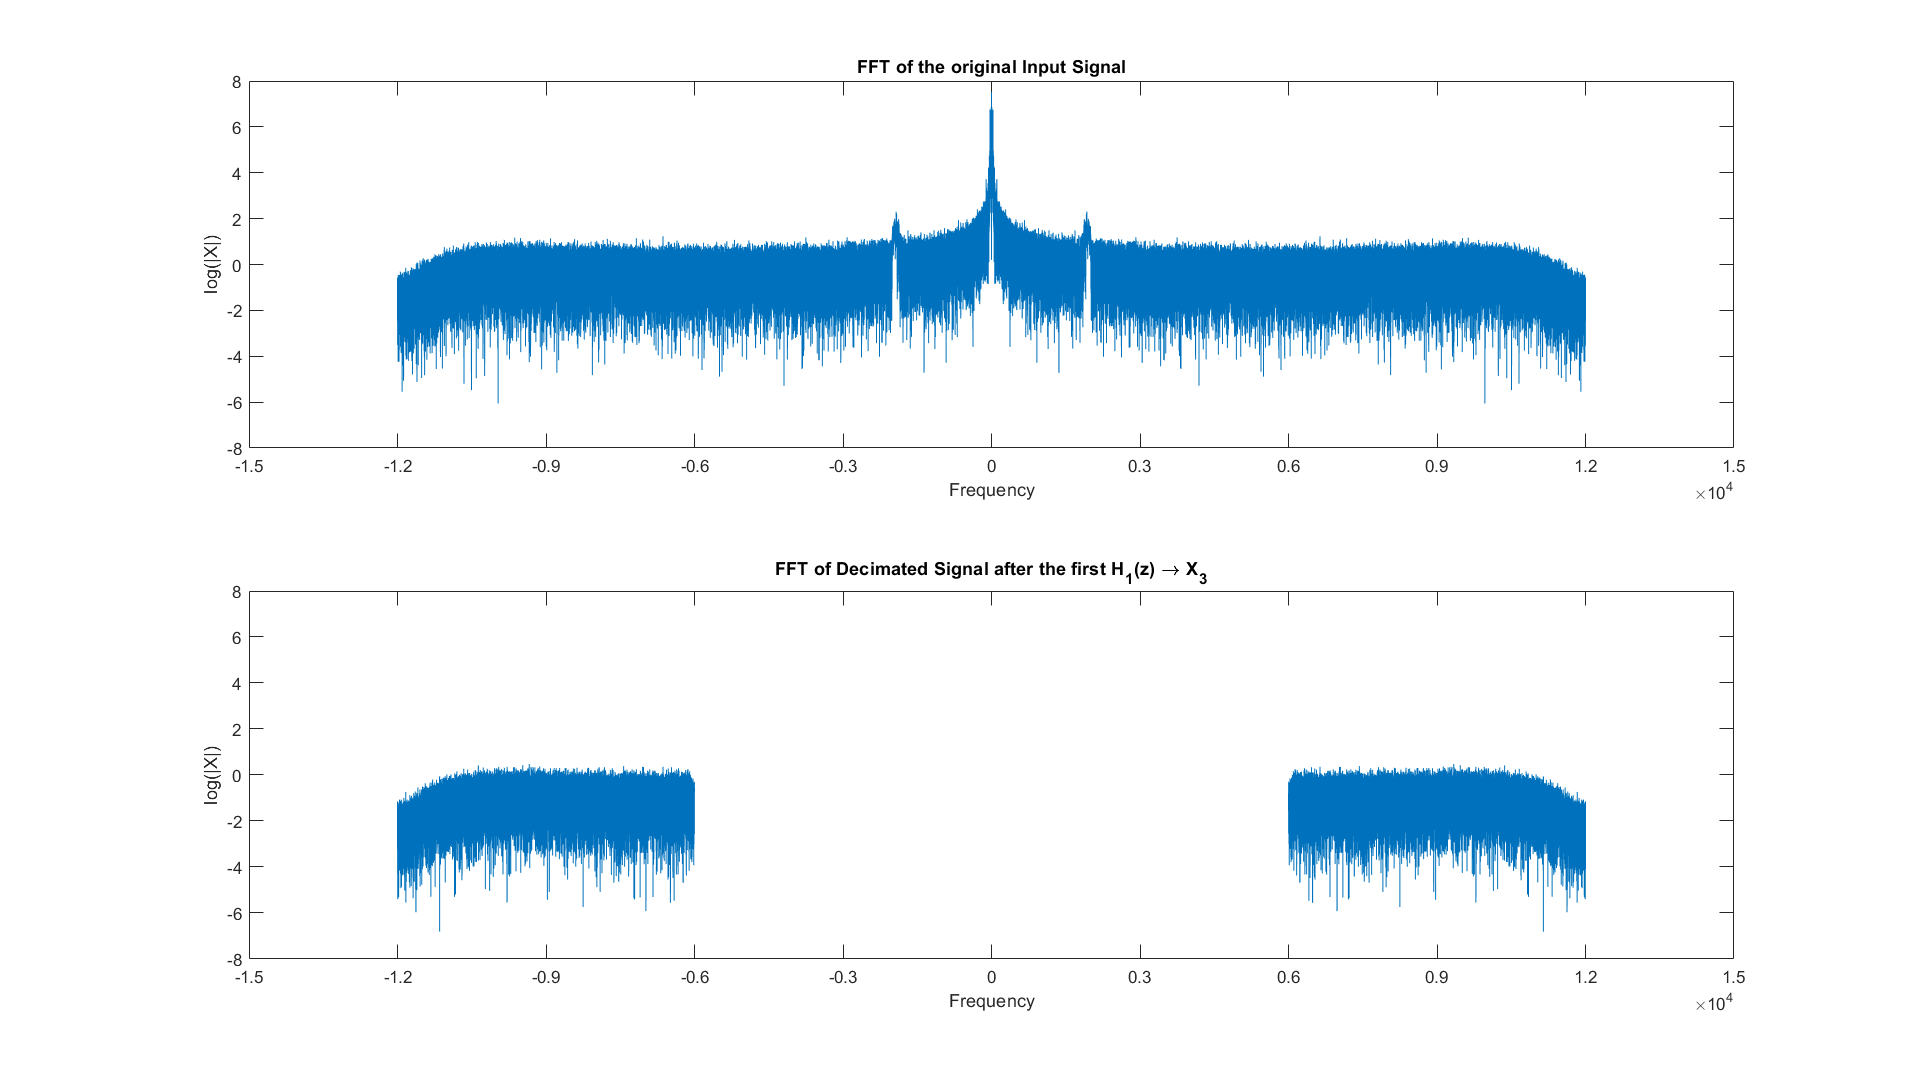

graph = figure;
subplot(212)
plot(decimatedSigHP1F(1:ceil(end/2)) - Fs2/2, decimatedSigHP1FFT(ceil(end/2):-1:1))
hold on
plot(decimatedSigHP1F(ceil(end/2):end) + Fs2/2, decimatedSigHP1FFT(end:-1:ceil(end/2)), 'color', [0, 0.4470, 0.7410])
title('FFT of Decimated Signal after the first H_1(z) \rightarrow X_3');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
hold off
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

You can see the first half of the decimated signal is corresponding to frequencies [-12000 -6000] and second half [6000 12000].

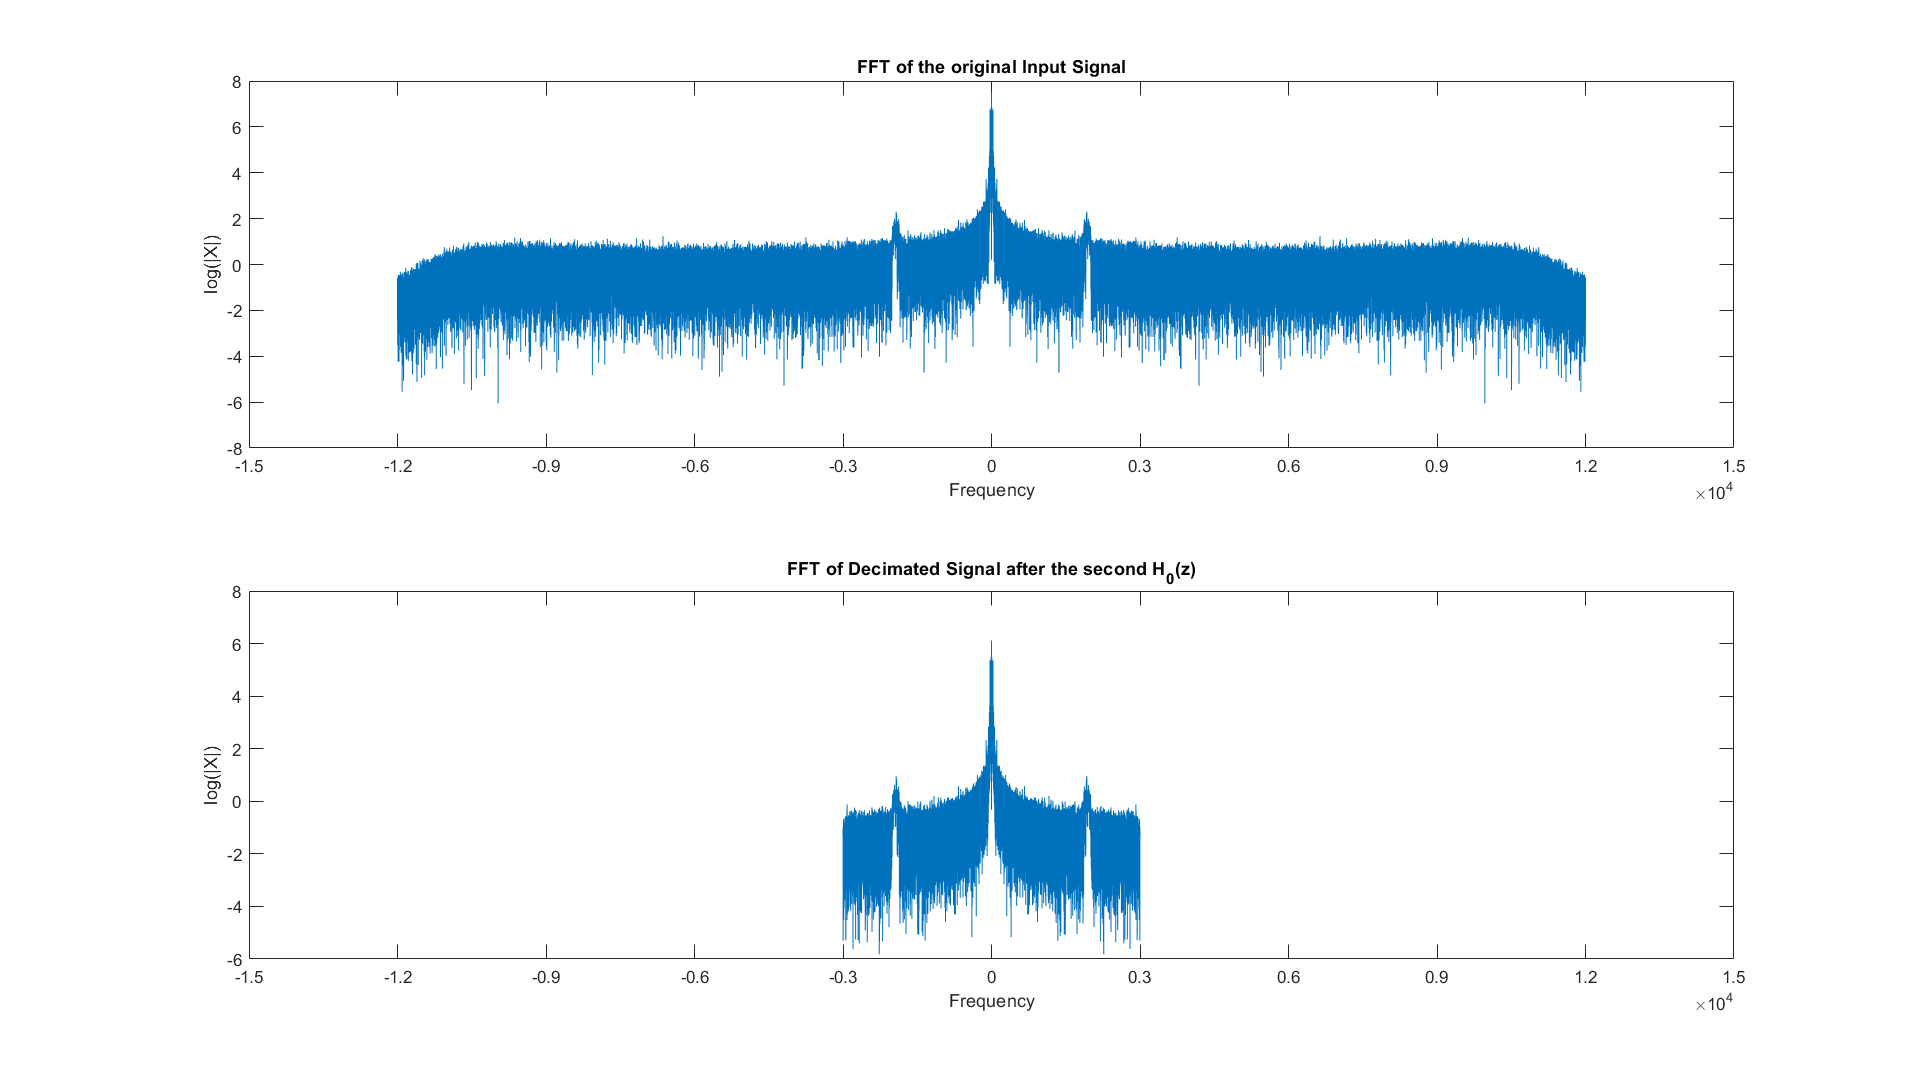

filteredSigLP2 = filter(LP_3K, decimatedSigLP1);

decimatedSigLP2= filteredSigLP2(1:M:end);

audiowrite("decimatedSigLP2.wav", decimatedSigLP2, Fs3);

decimatedSigLP2FFT = log(abs(fftshift(fft(decimatedSigLP2))));     % Zero-Centered FFT
decimatedSigLP2F = (-length(decimatedSigLP2)/2:...
    length(decimatedSigLP2)/2-1)...
    /length(decimatedSigLP2)*Fs3;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigLP2F, decimatedSigLP2FFT)
title('FFT of Decimated Signal after the second H_0(z)');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

*You can see how the frequency range has changed from [-6000  6000 Hz] to [-3000 3000 Hz] which represents the lower frequency band of the decimated signal. As you can see we are still seeing the quail call signature as it exists in this frequency range.*

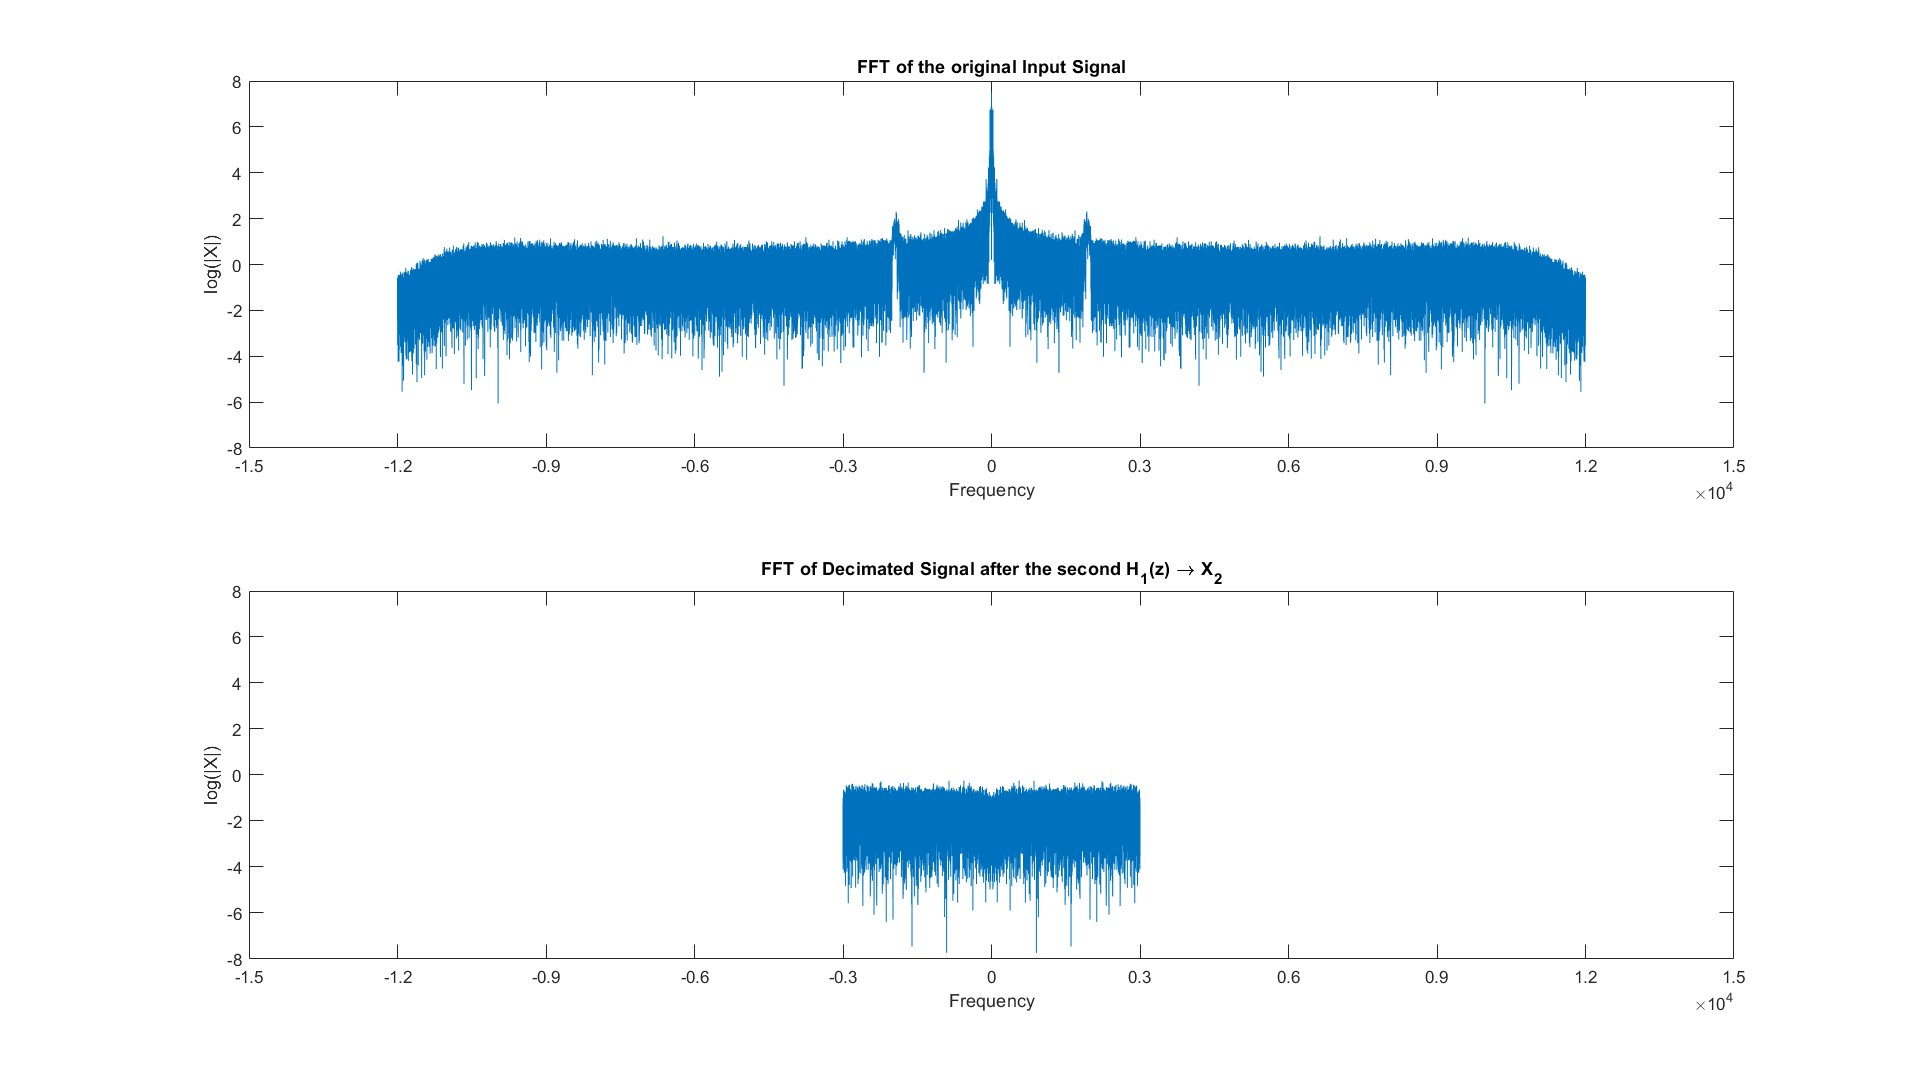

filteredSigHP2 = filter(HP_3K, decimatedSigLP1);

decimatedSigHP2= filteredSigHP2(1:M:end);

audiowrite("decimatedSigHP2.wav", decimatedSigHP2, Fs3);

decimatedSigHP2FFT = log(abs(fftshift(fft(decimatedSigHP2))));     % Zero-Centered FFT
decimatedSigHP2F = (-length(decimatedSigHP2)/2:...
    length(decimatedSigHP2)/2-1)...
    /length(decimatedSigHP2)*Fs3;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigHP2F, decimatedSigHP2FFT)
title('FFT of Decimated Signal after the second H_1(z) \rightarrow X_2');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

Again the same scenario as before is happening here. The graphs below show what frequencies are actually being represented after the second highpass decimation.

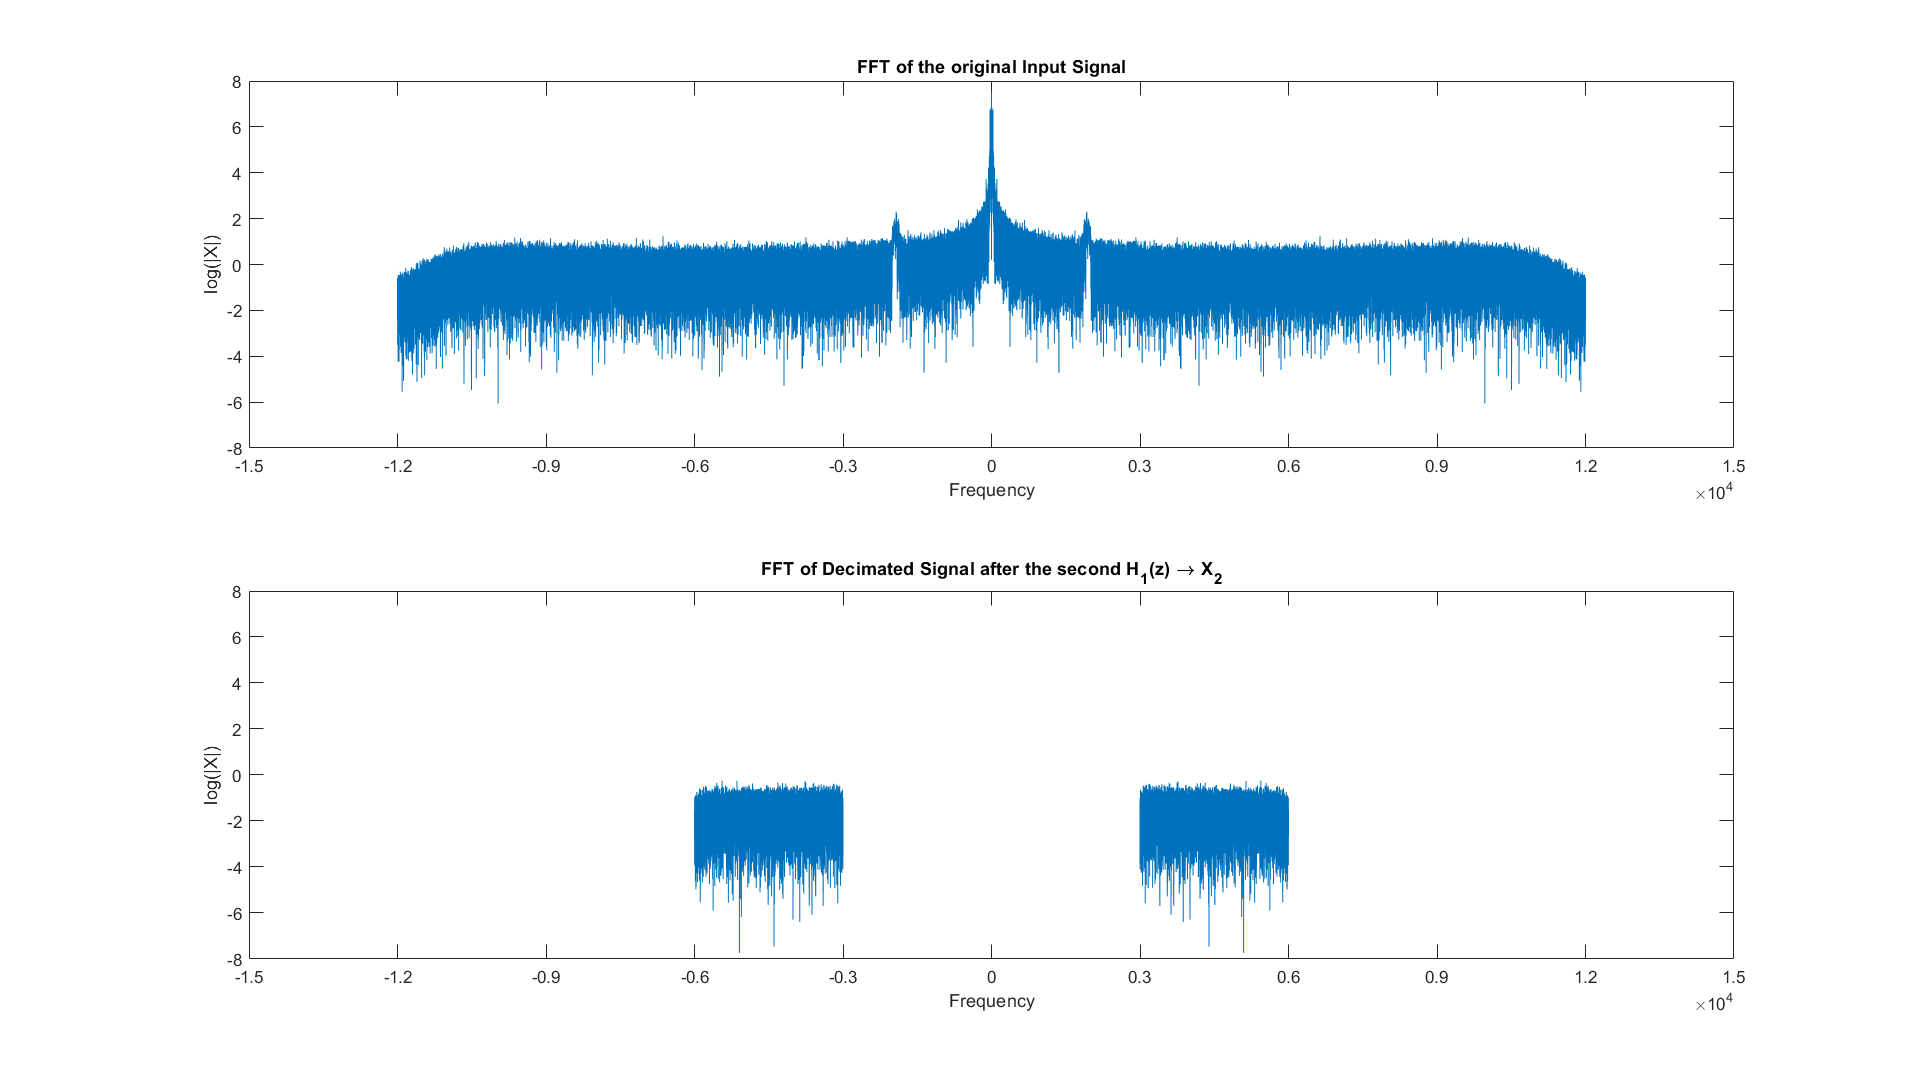

graph = figure;
subplot(212)
plot(decimatedSigHP2F(1:ceil(end/2)) - Fs3/2, decimatedSigHP2FFT(ceil(end/2):-1:1))
hold on
plot(decimatedSigHP2F(ceil(end/2):end) + Fs3/2, decimatedSigHP2FFT(end:-1:ceil(end/2)), 'color', [0, 0.4470, 0.7410])
title('FFT of Decimated Signal after the second H_1(z) \rightarrow X_2');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
hold off
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

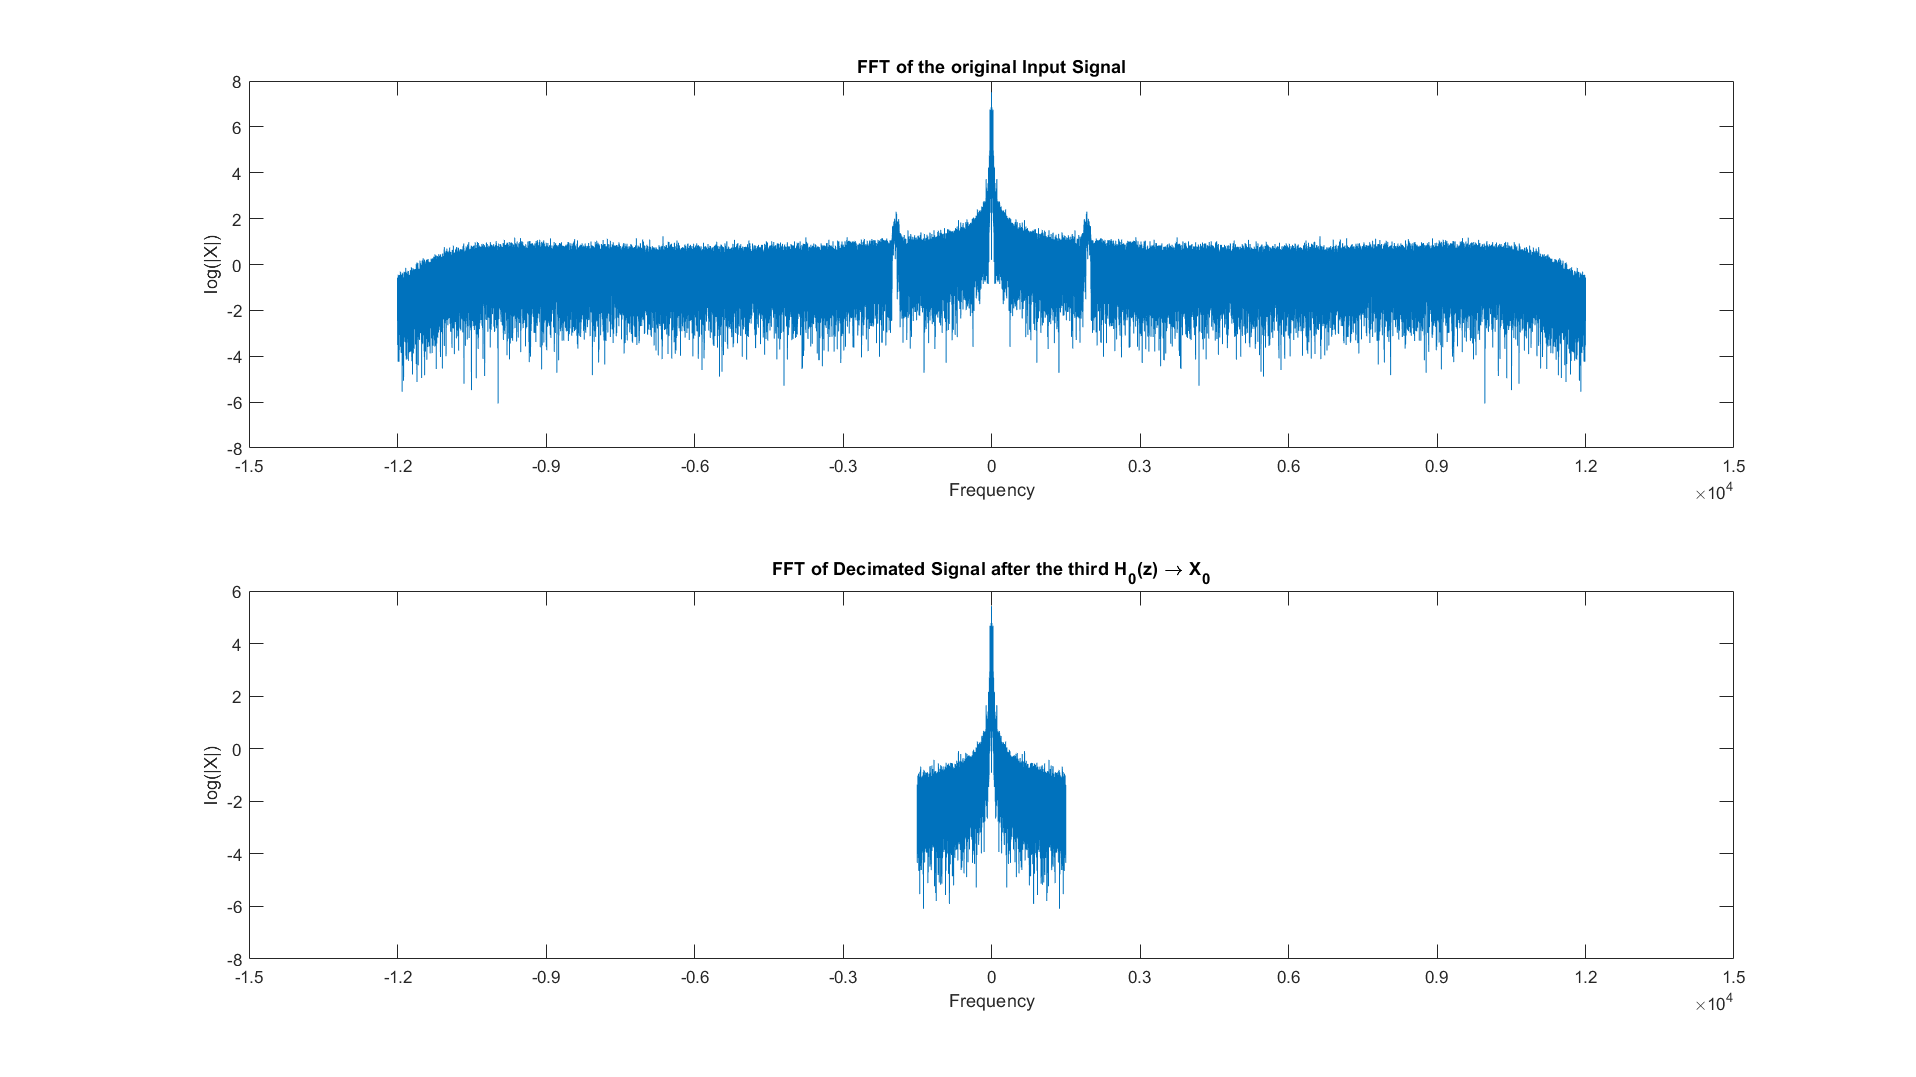

filteredSigLP3 = filter(LP_1500, decimatedSigLP2);

decimatedSigLP3 = filteredSigLP3(1:M:end);

audiowrite("decimatedSigLP3.wav", decimatedSigLP3, Fs3/2);

decimatedSigLP3FFT = log(abs(fftshift(fft(decimatedSigLP3))));     % Zero-Centered FFT
decimatedSigLP3F = (-length(decimatedSigLP3)/2:...
    length(decimatedSigLP3)/2-1)...
    /length(decimatedSigLP3)*Fs3/2;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigLP3F, decimatedSigLP3FFT)
title('FFT of Decimated Signal after the third H_0(z) \rightarrow X_0');
ylabel('log(|X|)')
xlabel('Frequency'); 
xlim([-15000 15000])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

*You can see how the frequency range has now changed from [-3000  3000 Hz] to [-1500 1500 Hz] which represents the lower frequency band of the second decimated signal. However, now we cannot see the quail signature anymore and this expected from our previous analysis. In the begining we showed that the frequency range for the quail calls are between 1850 Hz to 2400 Hz, therefore it makes sense that we cannot see the signatures in the  [-1500 1500 Hz]  range. *

*We should be able to see the signatures in the higher frequency band after applying the third *$H_1 \left(z\right)$. The figures below should demonstrate this:

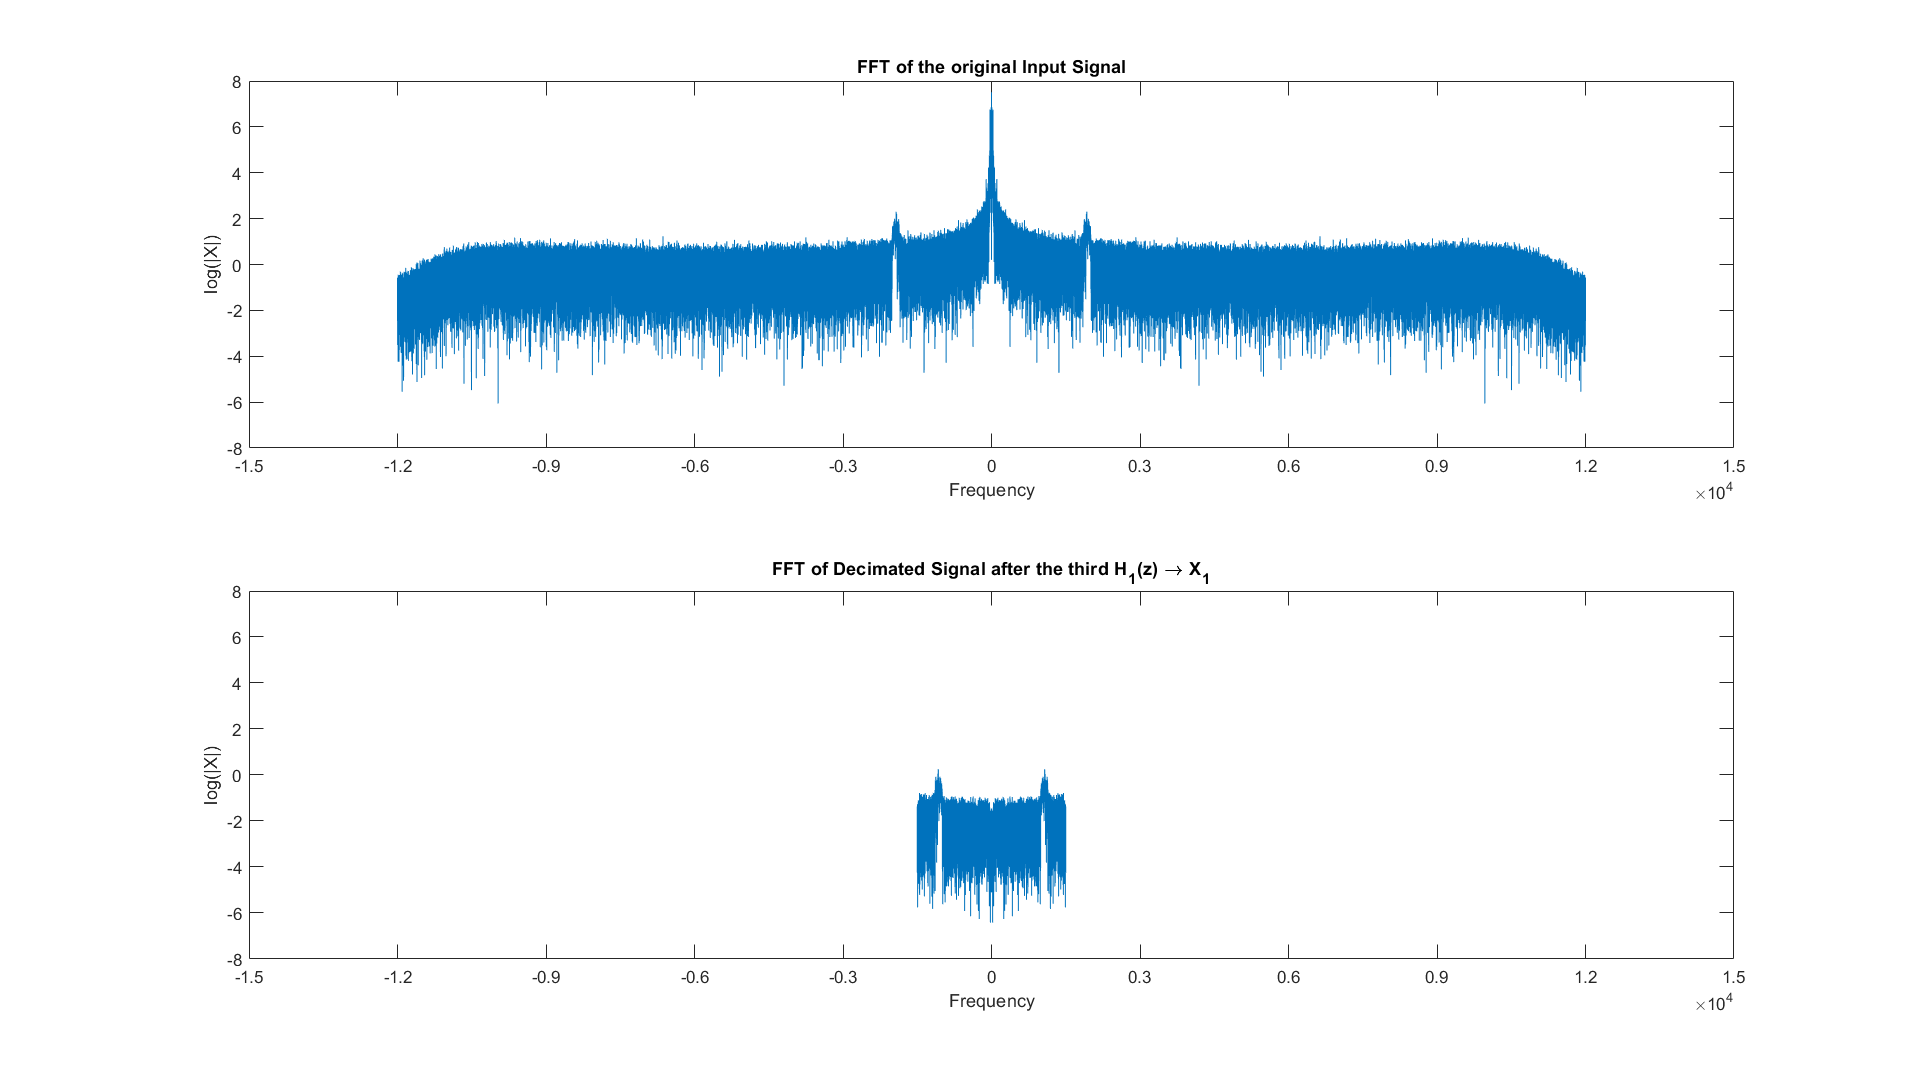

filteredSigHP3 = filter(HP_1500, decimatedSigLP2);

decimatedSigHP3= filteredSigHP3(1:M:end);

audiowrite("decimatedSigHP3.wav", decimatedSigHP3, Fs3/2);

decimatedSigHP3FFT = log(abs(fftshift(fft(decimatedSigHP3))));     % Zero-Centered FFT
decimatedSigHP3F = (-length(decimatedSigHP3)/2:...
    length(decimatedSigHP3)/2-1)...
    /length(decimatedSigHP3)*Fs3/2;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigHP3F, decimatedSigHP3FFT)
title('FFT of Decimated Signal after the third H_1(z) \rightarrow X_1');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

Notice now we can see signatures after the third highpass decimation which we couldn't see before after the lowpass decimation.

The graphs below show what frequencies are actually being represented after the third highpass decimation.

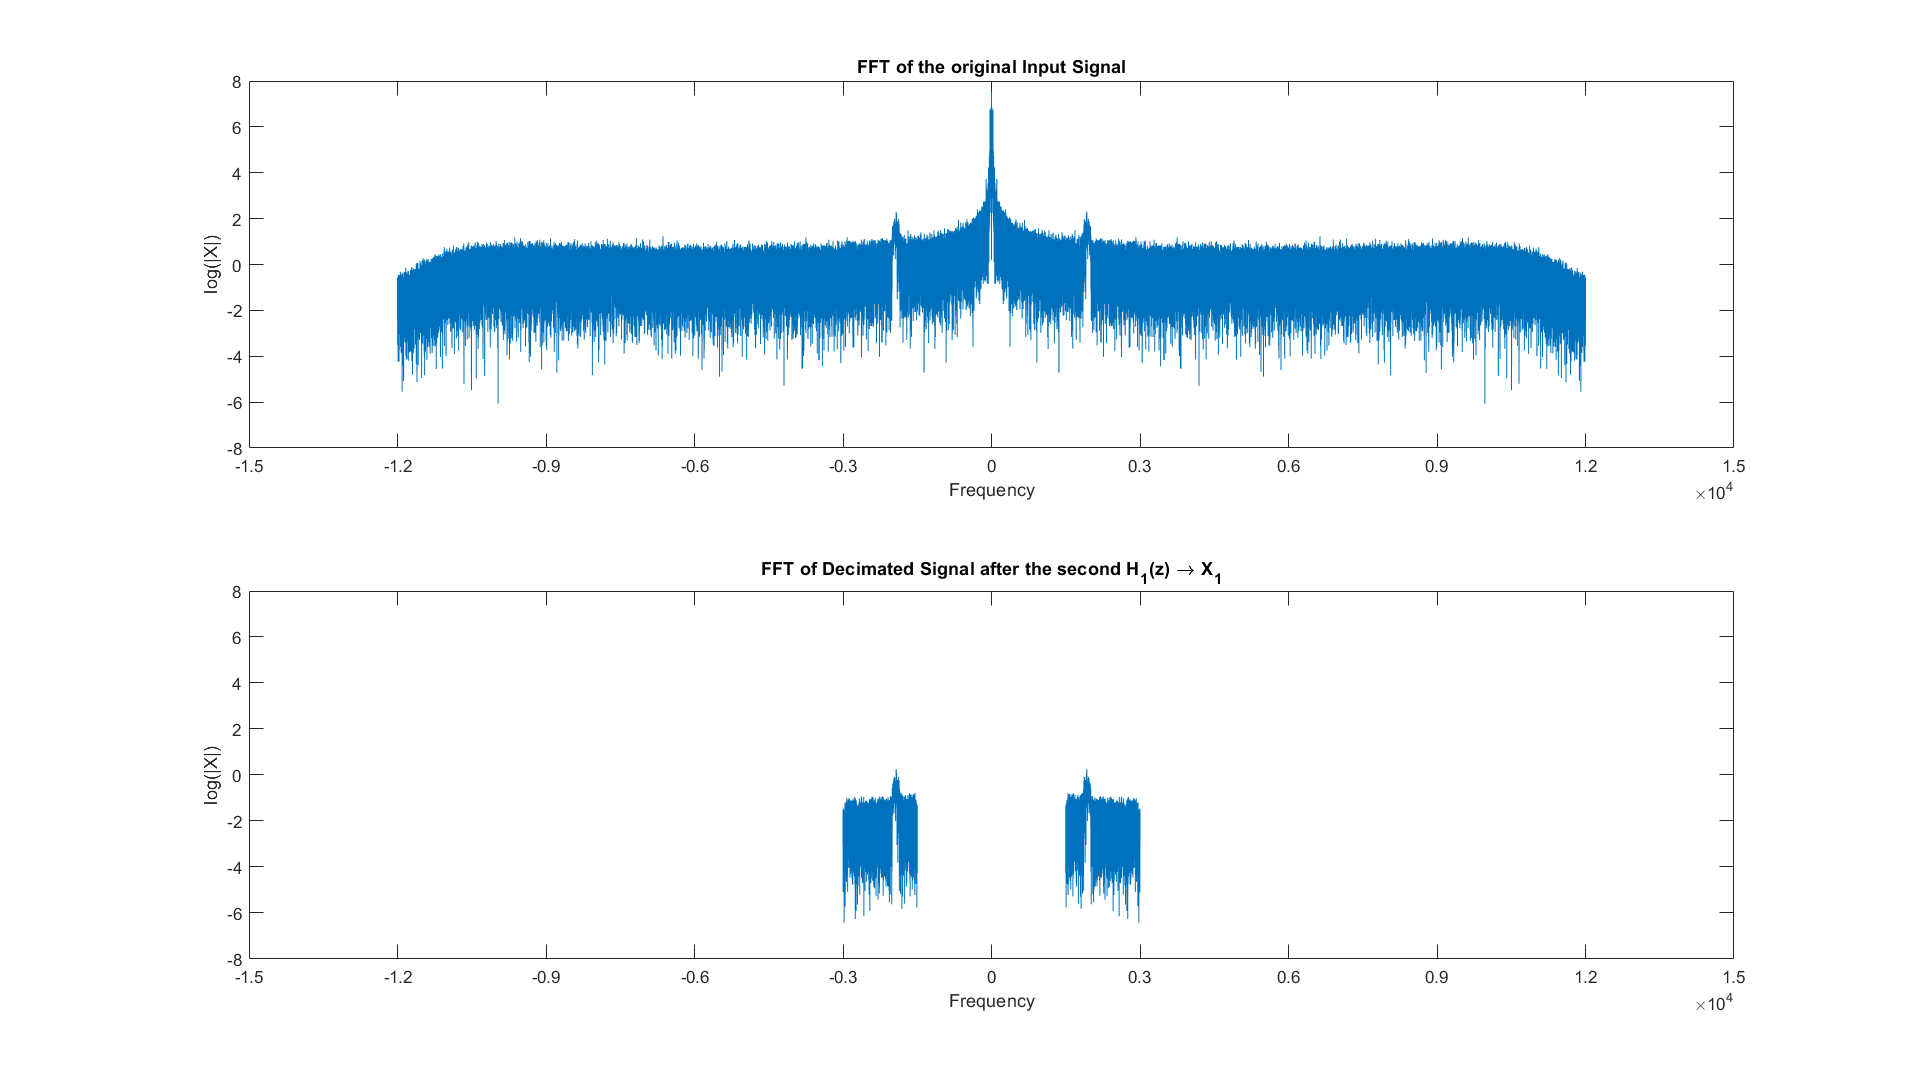

graph = figure;
subplot(212)
plot(decimatedSigHP3F(1:ceil(end/2)) - Fs3/4, decimatedSigHP3FFT(ceil(end/2):-1:1))
hold on
plot(decimatedSigHP3F(ceil(end/2):end) + Fs3/4, decimatedSigHP3FFT(end:-1:ceil(end/2)), 'color', [0, 0.4470, 0.7410])
title('FFT of Decimated Signal after the second H_1(z) \rightarrow X_1');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
hold off
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 1]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)